wind_vectors = {wind1(:), wind2(:), wind3(:), wind4(:), wind5(:), wind6(:)};
wind_names = {'wind1', 'wind2', 'wind3', 'wind4', 'wind5', 'wind6'};
sun_vectors = {sun1(:), sun2(:), sun3(:), sun4(:)};
sun_names = {'sun1', 'sun2', 'sun3', 'sun4'};

classicload = classicload(:);
fenshijijia = fenshijijia(:);
n = numel(wind_vectors{1});

% t 为连续变量，范围 [0.1, 1]，使用 fmincon (SQP) 求解
opts = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');

% 分别在以下约束下运行优化：sum(t) = beq
beq_values = [24, 21, 18, 15, 12];
Aeq = ones(1, n);
lb = 0.1 * ones(n, 1);
ub = ones(n, 1);

problem3_results = struct([]);
result_idx = 0;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    wind_name = wind_names{wind_idx};

    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};
        sun_name = sun_names{sun_idx};

        fprintf('\n\n==================== 情况 %02d：%s + %s ====================\n', ...
                (wind_idx - 1)*numel(sun_vectors) + sun_idx, wind_name, sun_name);

        for beq_idx = 1:numel(beq_values)
            beq = beq_values(beq_idx);

            fprintf('\n========== %s + %s, beq = %g, sum(t) = %g ==========\n', ...
                    wind_name, sun_name, beq, beq);

            % 初始点：均匀分布并截断到 [0.1, 1]，满足等式约束
            x0 = (beq / n) * ones(n, 1);

            t_opt = fmincon(@(t) objFun(t, classicload, wind, sun, fenshijijia), ...
                            x0, [], [], Aeq, beq, lb, ub, [], opts);
            t_opt = t_opt(:);
            J_min = objFun(t_opt, classicload, wind, sun, fenshijijia);
            fprintf('最小目标值 J = %.6g\n', J_min);
            disp('最优 t 向量：'); disp(t_opt);

            metrics = calcProblem3Metrics(t_opt, classicload, wind, sun, fenshijijia);

            problem3_nh3load = metrics.nh3load;
            problem3_load = metrics.load;
            problem3_generate = metrics.generate;
            problem3_buy = metrics.buy;
            problem3_sell = metrics.sell;
            problem3_buycost = metrics.buycost;
            problem3_dayload = metrics.dayload;
            problem3_daygenerate = metrics.daygenerate;
            problem3_daybuy = metrics.daybuy;
            problem3_daysell = metrics.daysell;
            problem3_xnyzf = metrics.xnyzf;
            problem3_zydl = metrics.zydl;
            problem3_xnysw = metrics.xnysw;

            fprintf('新能源自发自用电量占总可用发电量比例 = %.6g\n', problem3_xnyzf);
            fprintf('总用电量中绿电占比 = %.6g\n', problem3_zydl);
            fprintf('新能源上网电量比例 = %.6g\n', problem3_xnysw);

            result_idx = result_idx + 1;
            problem3_results(result_idx).case_idx = result_idx;
            problem3_results(result_idx).wind_idx = wind_idx;
            problem3_results(result_idx).wind_name = wind_name;
            problem3_results(result_idx).sun_idx = sun_idx;
            problem3_results(result_idx).sun_name = sun_name;
            problem3_results(result_idx).beq = beq;
            problem3_results(result_idx).t_opt = t_opt;
            problem3_results(result_idx).J_min = J_min;
            problem3_results(result_idx).nh3load = problem3_nh3load;
            problem3_results(result_idx).load = problem3_load;
            problem3_results(result_idx).generate = problem3_generate;
            problem3_results(result_idx).buy = problem3_buy;
            problem3_results(result_idx).sell = problem3_sell;
            problem3_results(result_idx).buycost = problem3_buycost;
            problem3_results(result_idx).dayload = problem3_dayload;
            problem3_results(result_idx).daygenerate = problem3_daygenerate;
            problem3_results(result_idx).daybuy = problem3_daybuy;
            problem3_results(result_idx).daysell = problem3_daysell;
            problem3_results(result_idx).xnyzf = problem3_xnyzf;
            problem3_results(result_idx).zydl = problem3_zydl;
            problem3_results(result_idx).xnysw = problem3_xnysw;
        end
    end
end



==================== 情况 01：wind1 + sun1 ====================



========== wind1 + sun1, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.430083e+03     0.000e+00     1.000e+00     0.000e+00     3.057e+02  
    1          50    5.430083e+03     0.000e+00     1.000e+00     0.000e+00     5.116e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 5430.08


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.644709


总用电量中绿电占比 = 0.592816


新能源上网电量比例 = 0.177646



========== wind1 + sun1, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.075817e+03     0.000e+00     1.000e+00     0.000e+00     3.663e+02  
    1          50    4.495798e+03     0.000e+00     1.000e+00     1.444e+00     2.512e+02  
    2          75    4.478745e+03     3.553e-15     1.000e+00     5.244e-01     1.443e+02  
    3         100    4.458681e+03     0.000e+00     1.000e+00     2.409e-01     1.344e+02  
    4         128    4.456918e+03     0.000e+00     3.430e-01     4.467e-02     1.296e+02  
    5         153    4.455519e+03     0.000e+00     1.000e+00     2.052e-02     1.500e+02  
    6         179    4.455499e+03     0.000e+00     7.000e-01     7.765e-03     1.285e+02  
    7         204    4.455102e+03     0.000e+00     1.000e+00     3.567e-03     1.285e+02  
    8         238    4.455064e+03     3.553e-15     4.035e-02     7.197e-04     1.

最小目标值 J = 4455.04


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8101
    0.3696
    0.1000
    0.1000
    0.8101
    0.8102
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.644709


总用电量中绿电占比 = 0.671987


新能源上网电量比例 = 0.177646



========== wind1 + sun1, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.611376e+03     0.000e+00     1.000e+00     0.000e+00     4.531e+02  
    1          50    3.764180e+03     3.553e-15     1.000e+00     1.843e+00     2.785e+02  
    2          75    3.764180e+03     3.553e-15     1.000e+00     8.923e-16     9.155e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 3764.18


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9400
    0.9400
    0.9400
    0.9400
    0.9400
    0.9400
    0.9400
    0.9400
    0.9400
    0.9400
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.493375


总用电量中绿电占比 = 0.704204


新能源上网电量比例 = 0.253312



========== wind1 + sun1, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    3.969455e+03     0.000e+00     1.000e+00     0.000e+00     5.865e+02  
    1          50    3.137960e+03     3.553e-15     1.000e+00     1.586e+00     3.355e+02  
    2          51    3.137960e+03     3.553e-15     7.000e-01     6.239e-16     5.045e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 3137.96


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.166502


总用电量中绿电占比 = 0.650303


新能源上网电量比例 = 0.416749



========== wind1 + sun1, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    3.028821e+03     0.000e+00     1.000e+00     0.000e+00     8.116e+02  
    1          50    2.218639e+03     1.776e-15     1.000e+00     1.655e+00     4.214e+02  
    2          75    2.218639e+03     3.553e-15     1.000e+00     7.880e-05     1.119e-04  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 2218.64


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3749
    0.3749
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = -0.107094


总用电量中绿电占比 = 0.608698


新能源上网电量比例 = 0.553547




==================== 情况 02：wind1 + sun2 ====================



========== wind1 + sun2, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.802670e+03     0.000e+00     1.000e+00     0.000e+00     2.485e+02  
    1          50    6.802670e+03     0.000e+00     1.000e+00     0.000e+00     4.547e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 6802.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.970389


总用电量中绿电占比 = 0.469144


新能源上网电量比例 = 0.0148055



========== wind1 + sun2, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.449472e+03     0.000e+00     1.000e+00     0.000e+00     3.009e+02  
    1          50    6.225244e+03     0.000e+00     1.000e+00     1.061e+00     2.902e+02  
    2          75    5.969872e+03     3.553e-15     1.000e+00     9.798e-01     2.909e+02  
    3         108    5.968624e+03     7.105e-15     5.765e-02     7.365e-02     2.491e+02  
    4         138    5.961282e+03     3.553e-15     1.681e-01     1.677e-01     3.942e+01  
    5         176    5.961154e+03     0.000e+00     9.689e-03     9.775e-03     3.943e+01  
    6         219    5.961146e+03     3.553e-15     1.628e-03     1.626e-03     2.402e+02  
    7         259    5.961084e+03     3.553e-15     4.748e-03     4.941e-03     2.402e+02  
    8         306    5.961079e+03     7.105e-15     3.910e-04     4.051e-04     2.

最小目标值 J = 5961.08


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9990
    0.9990
    0.9990
    0.8452
    0.8481
    0.9571
    1.0000
    0.8453
    0.9990
    0.9990
    0.9990
    0.2944
    0.1088
    0.1087
    0.9990
    0.9990
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.964759


总用电量中绿电占比 = 0.53028


新能源上网电量比例 = 0.0176207



========== wind1 + sun2, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.064984e+03     0.000e+00     1.000e+00     0.000e+00     3.724e+02  
    1          50    5.387651e+03     0.000e+00     1.000e+00     1.577e+00     3.636e+02  
    2          75    5.331333e+03     1.066e-14     1.000e+00     1.188e+00     2.390e+02  
    3         105    5.323698e+03     7.105e-15     1.681e-01     3.137e-01     1.480e+02  
    4         133    5.311998e+03     0.000e+00     3.430e-01     4.425e-01     1.880e+02  
    5         159    5.302652e+03     0.000e+00     7.000e-01     7.245e-01     1.885e+02  
    6         187    5.301012e+03     0.000e+00     3.430e-01     4.313e-01     1.886e+02  
    7         215    5.297012e+03     3.553e-15     3.430e-01     4.960e-01     1.889e+02  
    8         245    5.295506e+03     3.553e-15     1.681e-01     1.886e-01     2.

最小目标值 J = 5240.39


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.7558
    0.7558
    0.7205
    0.7890
    0.8481
    0.9912
    1.0000
    0.8453
    0.8177
    0.6754
    0.4018
    0.1691
    0.1000
    0.1000
    0.5152
    0.5151
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.970389


总用电量中绿电占比 = 0.613769


新能源上网电量比例 = 0.0148056



========== wind1 + sun2, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.610427e+03     0.000e+00     1.000e+00     0.000e+00     4.771e+02  
    1          50    4.718092e+03     1.776e-15     1.000e+00     2.008e+00     4.507e+02  
    2          76    4.704541e+03     1.776e-15     7.000e-01     6.660e-01     2.491e+02  
    3         102    4.657790e+03     1.776e-15     7.000e-01     1.030e+00     1.804e+02  
    4         130    4.651684e+03     3.553e-15     3.430e-01     2.396e-01     4.030e+02  
    5         169    4.651568e+03     1.776e-15     6.782e-03     5.315e-03     1.915e+02  
    6         201    4.648574e+03     0.000e+00     8.235e-02     1.105e-01     3.448e+02  
    7         226    4.608688e+03     0.000e+00     1.000e+00     8.052e-01     3.858e+02  
    8         251    4.608688e+03     0.000e+00     1.000e+00     4.627e-05     1.

最小目标值 J = 4608.69


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1000
    0.4783
    0.6690
    0.6716
    0.6716
    0.9906
    1.0000
    0.6716
    0.6690
    0.4783
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.709922


总用电量中绿电占比 = 0.629694


新能源上网电量比例 = 0.145039



========== wind1 + sun2, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.016190e+03     0.000e+00     1.000e+00     0.000e+00     6.459e+02  
    1          50    4.037039e+03     0.000e+00     1.000e+00     1.793e+00     4.074e+02  
    2          75    4.037039e+03     1.776e-15     1.000e+00     8.685e-05     1.221e-04  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 4037.04


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3400
    0.3400
    0.3400
    0.3400
    0.3400
    0.3400
    0.3400
    0.3399
    0.3399
    0.3398
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.215093


总用电量中绿电占比 = 0.547179


新能源上网电量比例 = 0.392454




==================== 情况 03：wind1 + sun3 ====================



========== wind1 + sun3, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.163382e+03     0.000e+00     1.000e+00     0.000e+00     1.918e+02  
    1          50    8.163382e+03     0.000e+00     1.000e+00     0.000e+00     4.547e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 8163.38


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.319332


新能源上网电量比例 = 0



========== wind1 + sun3, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.937114e+03     0.000e+00     1.000e+00     0.000e+00     2.300e+02  
    1          50    7.505646e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    7.505646e+03     0.000e+00     1.000e+00     0.000e+00     2.842e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 7505.65


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.361979


新能源上网电量比例 = 0



========== wind1 + sun3, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.635424e+03     0.000e+00     1.000e+00     0.000e+00     2.851e+02  
    1          50    6.933908e+03     0.000e+00     1.000e+00     1.732e+00     2.868e+02  
    2          75    6.805017e+03     0.000e+00     1.000e+00     7.302e-01     2.978e+02  
    3         108    6.803353e+03     3.553e-15     5.765e-02     6.908e-02     1.768e+02  
    4         135    6.761311e+03     3.553e-15     4.900e-01     4.531e-01     2.577e+02  
    5         165    6.757723e+03     3.553e-15     1.681e-01     9.194e-02     2.443e+02  
    6         193    6.738892e+03     3.553e-15     3.430e-01     3.245e-01     1.799e+02  
    7         223    6.736679e+03     0.000e+00     1.681e-01     9.065e-02     2.001e+02  
    8         251    6.728632e+03     3.553e-15     3.430e-01     2.224e-01     1.

最小目标值 J = 6704.87


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9364
    0.9365
    0.9365
    0.3726
    0.3700
    0.4669
    0.6243
    0.3518
    0.9365
    0.9366
    0.9362
    0.1228
    0.1000
    0.1000
    0.9364
    0.9365
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.417773


新能源上网电量比例 = 4.94693e-09



========== wind1 + sun3, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.213057e+03     0.000e+00     1.000e+00     0.000e+00     3.703e+02  
    1          50    6.393435e+03     0.000e+00     1.000e+00     1.873e+00     3.363e+02  
    2          75    6.157411e+03     1.776e-15     1.000e+00     9.185e-01     2.252e+02  
    3         102    6.146182e+03     0.000e+00     4.900e-01     4.626e-01     2.260e+02  
    4         132    6.139867e+03     3.553e-15     1.681e-01     1.581e-01     2.264e+02  
    5         159    6.118815e+03     3.553e-15     4.900e-01     5.380e-01     2.275e+02  
    6         185    6.090408e+03     1.776e-15     7.000e-01     3.810e-01     2.140e+02  
    7         214    6.077703e+03     1.776e-15     2.401e-01     2.749e-01     3.624e+02  
    8         256    6.077569e+03     0.000e+00     2.326e-03     2.552e-03     2.

最小目标值 J = 6031.83


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.4997
    0.5703
    0.5703
    0.3726
    0.3700
    0.4669
    0.6243
    0.3518
    0.5703
    0.5704
    0.5699
    0.1228
    0.1000
    0.1000
    0.5704
    0.5703
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.493902


新能源上网电量比例 = 1.85292e-09



========== wind1 + sun3, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.640355e+03     0.000e+00     1.000e+00     0.000e+00     5.106e+02  
    1          50    5.545436e+03     3.553e-15     1.000e+00     1.932e+00     5.801e+02  
    2          75    5.535627e+03     1.776e-15     1.000e+00     1.277e+00     2.402e+02  
    3         101    5.482294e+03     1.776e-15     7.000e-01     1.127e+00     2.536e+02  
    4         129    5.475696e+03     3.553e-15     3.430e-01     4.880e-01     2.542e+02  
    5         155    5.324852e+03     3.553e-15     7.000e-01     9.076e-01     3.708e+02  
    6         183    5.313785e+03     1.776e-15     3.430e-01     3.915e-01     2.565e+02  
    7         210    5.265663e+03     1.776e-15     4.900e-01     6.053e-01     4.048e+02  
    8         241    5.262029e+03     1.776e-15     1.176e-01     1.452e-01     4.

最小目标值 J = 5224.53


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3346
    0.2787
    0.3667
    0.3066
    0.3066
    0.3622
    0.6108
    0.2916
    0.2930
    0.2115
    0.1162
    0.1217
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.811974


总用电量中绿电占比 = 0.547179


新能源上网电量比例 = 0.0940132




==================== 情况 04：wind1 + sun4 ====================



========== wind1 + sun4, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.711892e+03     0.000e+00     1.000e+00     0.000e+00     1.690e+02  
    1          50    8.711892e+03     0.000e+00     1.000e+00     0.000e+00     3.979e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 8711.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.258161


新能源上网电量比例 = 0



========== wind1 + sun4, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.563983e+03     0.000e+00     1.000e+00     0.000e+00     2.002e+02  
    1          50    8.132515e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    8.132515e+03     3.553e-15     1.000e+00     8.632e-05     6.038e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 8132.51


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.292639


新能源上网电量比例 = 0



========== wind1 + sun4, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.366771e+03     0.000e+00     1.000e+00     0.000e+00     2.445e+02  
    1          50    7.432148e+03     0.000e+00     1.000e+00     1.732e+00     2.738e+02  
    2          75    7.427993e+03     0.000e+00     1.000e+00     7.348e-01     2.736e+02  
    3         105    7.420415e+03     0.000e+00     1.681e-01     1.866e-01     2.614e+02  
    4         134    7.419942e+03     0.000e+00     2.401e-01     3.580e-01     9.587e+01  
    5         159    7.383706e+03     0.000e+00     1.000e+00     3.122e-01     3.242e+02  
    6         184    7.376253e+03     0.000e+00     1.000e+00     2.777e-01     3.236e+02  
    7         215    7.374165e+03     3.553e-15     1.176e-01     9.420e-02     2.735e+00  
    8         240    7.360011e+03     7.105e-15     1.000e+00     6.275e-02     1.

最小目标值 J = 7360.01


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3427
    0.1434
    0.2734
    0.5976
    0.3428
    1.0000
    1.0000
    1.0000
    0.1000
    0.1000
    0.1000
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.337746


新能源上网电量比例 = 0



========== wind1 + sun4, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.090674e+03     0.000e+00     1.000e+00     0.000e+00     3.118e+02  
    1          50    6.887794e+03     0.000e+00     1.000e+00     1.873e+00     3.108e+02  
    2          76    6.847842e+03     5.329e-15     7.000e-01     5.656e-01     2.083e+02  
    3         102    6.829472e+03     0.000e+00     7.000e-01     5.142e-01     2.071e+02  
    4         134    6.827754e+03     3.553e-15     8.235e-02     5.010e-02     1.845e+02  
    5         160    6.794991e+03     1.776e-15     7.000e-01     5.841e-01     2.048e+02  
    6         189    6.784003e+03     0.000e+00     2.401e-01     1.124e-01     2.041e+02  
    7         216    6.771493e+03     0.000e+00     4.900e-01     3.782e-01     2.032e+02  
    8         252    6.770784e+03     3.553e-15     1.977e-02     1.486e-02     2.

最小目标值 J = 6733.4


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6836
    0.6839
    0.6836
    0.1876
    0.1233
    0.2510
    0.4701
    0.1975
    0.6838
    0.6837
    0.6839
    0.1000
    0.1000
    0.1000
    0.6839
    0.6841
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.399292


新能源上网电量比例 = 1.02337e-08



========== wind1 + sun4, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.676528e+03     0.000e+00     1.000e+00     0.000e+00     4.243e+02  
    1          50    6.110299e+03     1.776e-15     1.000e+00     1.833e+00     3.584e+02  
    2          75    6.063363e+03     0.000e+00     1.000e+00     8.701e-01     2.994e+02  
    3         101    6.047743e+03     1.776e-15     7.000e-01     5.944e-01     3.007e+02  
    4         128    5.975826e+03     1.776e-15     4.900e-01     7.374e-01     2.073e+02  
    5         158    5.945649e+03     1.776e-15     1.681e-01     2.695e-01     3.244e+02  
    6         188    5.943930e+03     3.553e-15     1.681e-01     1.765e-01     3.517e+02  
    7         223    5.943269e+03     1.776e-15     2.825e-02     3.319e-02     3.518e+02  
    8         251    5.925378e+03     0.000e+00     3.430e-01     3.035e-01     3.

最小目标值 J = 5899.24


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5735
    0.4951
    0.3107
    0.1876
    0.1233
    0.2510
    0.4701
    0.1975
    0.2108
    0.4979
    0.1275
    0.1000
    0.1000
    0.1000
    0.1275
    0.1275
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.488266


新能源上网电量比例 = 4.02852e-09




==================== 情况 05：wind2 + sun1 ====================



========== wind2 + sun1, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.835935e+03     0.000e+00     1.000e+00     0.000e+00     2.888e+02  
    1          50    5.835935e+03     0.000e+00     1.000e+00     0.000e+00     5.684e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 5835.93


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.727997


总用电量中绿电占比 = 0.538735


新能源上网电量比例 = 0.136002



========== wind2 + sun1, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.495370e+03     0.000e+00     1.000e+00     0.000e+00     3.463e+02  
    1          50    4.958442e+03     7.105e-15     1.000e+00     1.440e+00     2.533e+02  
    2          75    4.943287e+03     3.553e-15     1.000e+00     4.977e-01     1.430e+02  
    3         100    4.923367e+03     3.553e-15     1.000e+00     2.134e-01     1.298e+02  
    4         130    4.920135e+03     0.000e+00     1.681e-01     5.693e-02     1.497e+02  
    5         156    4.919297e+03     0.000e+00     7.000e-01     2.153e-02     1.225e+02  
    6         181    4.918551e+03     0.000e+00     1.000e+00     9.878e-03     1.511e+02  
    7         208    4.918439e+03     3.553e-15     4.900e-01     2.622e-03     1.285e+02  
    8         233    4.918358e+03     3.553e-15     1.000e+00     1.207e-03     1.

最小目标值 J = 4918.33


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8627
    0.9838
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8627
    0.3653
    0.1000
    0.1000
    0.8627
    0.8628
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.727997


总用电量中绿电占比 = 0.610684


新能源上网电量比例 = 0.136002



========== wind2 + sun1, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.075039e+03     0.000e+00     1.000e+00     0.000e+00     4.274e+02  
    1          50    4.289826e+03     7.105e-15     1.000e+00     1.911e+00     2.820e+02  
    2          75    4.222077e+03     0.000e+00     1.000e+00     7.225e-01     1.370e+02  
    3         103    4.222077e+03     0.000e+00     3.430e-01     5.778e-05     8.999e+01  
    4         128    4.222077e+03     0.000e+00     1.000e+00     7.310e-05     4.626e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在

最小目标值 J = 4222.08


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5679
    0.6822
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9999
    0.6821
    0.5679
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.612034


总用电量中绿电占比 = 0.657515


新能源上网电量比例 = 0.193983



========== wind2 + sun1, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.520591e+03     0.000e+00     1.000e+00     0.000e+00     5.498e+02  
    1          50    3.687436e+03     1.776e-15     1.000e+00     1.586e+00     3.354e+02  
    2          75    3.687436e+03     0.000e+00     1.000e+00     4.976e-16     6.104e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 3687.44


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.234134


总用电量中绿电占比 = 0.595105


新能源上网电量比例 = 0.382933



========== wind2 + sun1, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    3.718194e+03     0.000e+00     1.000e+00     0.000e+00     7.541e+02  
    1          50    2.885474e+03     1.776e-15     1.000e+00     1.779e+00     4.196e+02  
    2          78    2.885474e+03     0.000e+00     3.430e-01     1.339e-05     2.757e+02  
    3         105    2.885474e+03     0.000e+00     4.900e-01     2.502e-04     1.406e+02  
    4         130    2.885474e+03     0.000e+00     1.000e+00     1.602e-16     5.595e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在

最小目标值 J = 2885.47


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3182
    0.3182
    0.3182
    0.3182
    0.3182
    0.3182
    0.3182
    0.3180
    0.3180
    0.3183
    0.3183
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = -0.143767


总用电量中绿电占比 = 0.504882


新能源上网电量比例 = 0.571883




==================== 情况 06：wind2 + sun2 ====================



========== wind2 + sun2, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.365760e+03     0.000e+00     1.000e+00     0.000e+00     2.251e+02  
    1          50    7.365760e+03     0.000e+00     1.000e+00     0.000e+00     5.684e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 7365.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.378855


新能源上网电量比例 = 0



========== wind2 + sun2, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.064377e+03     0.000e+00     1.000e+00     0.000e+00     2.716e+02  
    1          50    6.760696e+03     3.553e-15     1.000e+00     1.194e+00     2.940e+02  
    2          75    6.612217e+03     7.105e-15     1.000e+00     8.216e-01     2.624e+02  
    3         105    6.610978e+03     7.105e-15     1.681e-01     1.942e-01     1.730e+02  
    4         130    6.610641e+03     0.000e+00     1.000e+00     1.453e-01     2.796e+02  
    5         155    6.594078e+03     0.000e+00     1.000e+00     2.163e-01     2.707e+02  
    6         180    6.594078e+03     0.000e+00     1.000e+00     0.000e+00     6.253e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿


最小目标值 J = 6594.08


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.7780
    0.7779
    0.9649
    1.0000
    0.9649
    1.0000
    1.0000
    1.0000
    0.3145
    0.1000
    0.1000
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.429452


新能源上网电量比例 = 0



========== wind2 + sun2, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.744498e+03     0.000e+00     1.000e+00     0.000e+00     3.346e+02  
    1          50    6.123965e+03     0.000e+00     1.000e+00     1.568e+00     3.605e+02  
    2          75    6.090767e+03     3.553e-15     1.000e+00     9.811e-01     1.961e+02  
    3         105    6.071501e+03     0.000e+00     1.681e-01     3.753e-01     1.649e+02  
    4         133    6.067068e+03     0.000e+00     3.430e-01     3.522e-01     1.767e+02  
    5         158    6.019278e+03     3.553e-15     1.000e+00     6.833e-01     3.261e+02  
    6         188    6.000512e+03     0.000e+00     1.681e-01     2.667e-01     3.223e+02  
    7         218    5.999727e+03     3.553e-15     1.681e-01     2.903e-01     2.930e+02  
    8         253    5.999624e+03     0.000e+00     2.825e-02     4.554e-02     1.

最小目标值 J = 5943.51


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6794
    0.6793
    0.6794
    0.6307
    0.7651
    0.8855
    0.9932
    0.8852
    0.7486
    0.6512
    0.6793
    0.1649
    0.1000
    0.1000
    0.6793
    0.6789
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.495647


新能源上网电量比例 = 5.6945e-09



========== wind2 + sun2, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.363592e+03     0.000e+00     1.000e+00     0.000e+00     4.269e+02  
    1          50    5.544834e+03     1.776e-15     1.000e+00     2.174e+00     4.457e+02  
    2          75    5.342360e+03     3.553e-15     1.000e+00     1.071e+00     3.030e+02  
    3         105    5.325761e+03     0.000e+00     1.681e-01     2.808e-01     1.878e+02  
    4         131    5.310216e+03     5.329e-15     7.000e-01     8.126e-01     3.051e+02  
    5         158    5.309162e+03     3.553e-15     4.900e-01     6.345e-01     3.052e+02  
    6         188    5.285347e+03     1.776e-15     1.681e-01     3.470e-01     2.666e+02  
    7         215    5.268040e+03     0.000e+00     4.900e-01     6.433e-01     1.905e+02  
    8         245    5.255430e+03     0.000e+00     1.681e-01     1.826e-01     1.

最小目标值 J = 5158.16


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1458
    0.2599
    0.4286
    0.6133
    0.7559
    0.8808
    0.9905
    0.8792
    0.7229
    0.5012
    0.2682
    0.1538
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.960853


总用电量中绿电占比 = 0.574497


新能源上网电量比例 = 0.0195737



========== wind2 + sun2, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.860393e+03     0.000e+00     1.000e+00     0.000e+00     5.756e+02  
    1          50    4.723885e+03     1.776e-15     1.000e+00     1.861e+00     3.942e+02  
    2          51    4.723885e+03     1.776e-15     7.000e-01     3.698e-16     1.847e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 4723.88


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1000
    0.1000
    0.1000
    0.4429
    0.4429
    0.4429
    0.4429
    0.4429
    0.4429
    0.4429
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.338888


总用电量中绿电占比 = 0.479682


新能源上网电量比例 = 0.330556




==================== 情况 07：wind2 + sun3 ====================



========== wind2 + sun3, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.770396e+03     0.000e+00     1.000e+00     0.000e+00     1.665e+02  
    1          50    8.770396e+03     0.000e+00     1.000e+00     0.000e+00     3.979e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 8770.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.221993


新能源上网电量比例 = 0



========== wind2 + sun3, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.630845e+03     0.000e+00     1.000e+00     0.000e+00     1.970e+02  
    1          50    8.199377e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    8.199377e+03     0.000e+00     1.000e+00     0.000e+00     2.842e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 8199.38


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.25164


新能源上网电量比例 = 0



========== wind2 + sun3, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.444776e+03     0.000e+00     1.000e+00     0.000e+00     2.402e+02  
    1          50    7.593922e+03     0.000e+00     1.000e+00     1.732e+00     2.785e+02  
    2          75    7.553297e+03     3.553e-15     1.000e+00     6.405e-01     2.982e+02  
    3         110    7.551486e+03     3.553e-15     2.825e-02     4.940e-02     2.940e+02  
    4         137    7.524915e+03     0.000e+00     4.900e-01     5.631e-01     2.294e+02  
    5         167    7.520337e+03     0.000e+00     1.681e-01     1.441e-01     2.201e+02  
    6         195    7.515960e+03     0.000e+00     3.430e-01     2.837e-01     2.812e+02  
    7         225    7.513701e+03     3.553e-15     1.681e-01     1.329e-01     2.794e+02  
    8         252    7.512535e+03     0.000e+00     4.900e-01     2.337e-01     1.

最小目标值 J = 7439.64


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9985
    0.9986
    0.9985
    0.2144
    0.2870
    0.3612
    0.4380
    0.3917
    0.9987
    0.9987
    0.9987
    0.1186
    0.1000
    0.1000
    0.9987
    0.9989
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.290427


新能源上网电量比例 = 4.95352e-09



========== wind2 + sun3, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.184281e+03     0.000e+00     1.000e+00     0.000e+00     3.056e+02  
    1          50    7.169841e+03     0.000e+00     1.000e+00     1.873e+00     3.233e+02  
    2          75    7.026247e+03     3.553e-15     1.000e+00     9.185e-01     2.261e+02  
    3         105    7.023221e+03     3.553e-15     1.681e-01     1.587e-01     2.263e+02  
    4         131    7.007620e+03     1.776e-15     7.000e-01     4.649e-01     2.273e+02  
    5         159    7.003359e+03     1.776e-15     3.430e-01     1.924e-01     2.276e+02  
    6         184    6.975323e+03     3.553e-15     1.000e+00     3.203e-01     2.295e+02  
    7         220    6.974782e+03     3.553e-15     1.977e-02     3.138e-02     2.295e+02  
    8         252    6.973746e+03     3.553e-15     8.235e-02     1.167e-01     2.

最小目标值 J = 6913.56


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6237
    0.6236
    0.6238
    0.2144
    0.2870
    0.3612
    0.4380
    0.3917
    0.6233
    0.6238
    0.6236
    0.1186
    0.1000
    0.1000
    0.6235
    0.6237
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.343351


新能源上网电量比例 = 5.28795e-09



========== wind2 + sun3, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.793537e+03     0.000e+00     1.000e+00     0.000e+00     4.145e+02  
    1          50    6.444793e+03     3.553e-15     1.000e+00     1.833e+00     3.766e+02  
    2          75    6.273519e+03     1.776e-15     1.000e+00     6.998e-01     2.999e+02  
    3         104    6.234235e+03     3.553e-15     2.401e-01     2.754e-01     3.032e+02  
    4         131    6.219069e+03     1.776e-15     4.900e-01     4.455e-01     3.045e+02  
    5         160    6.194616e+03     1.776e-15     2.401e-01     2.640e-01     3.065e+02  
    6         191    6.187543e+03     1.776e-15     1.176e-01     1.179e-01     2.852e+02  
    7         220    6.167113e+03     1.776e-15     2.401e-01     2.386e-01     2.846e+02  
    8         252    6.165111e+03     3.553e-15     8.235e-02     9.130e-02     2.

最小目标值 J = 6124.45


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.2604
    0.2549
    0.3327
    0.2144
    0.2870
    0.3612
    0.4380
    0.3917
    0.2806
    0.1800
    0.1611
    0.1186
    0.1000
    0.1000
    0.2602
    0.2592
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.41986


新能源上网电量比例 = 1.35412e-08




==================== 情况 08：wind2 + sun4 ====================



========== wind2 + sun4, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    9.318906e+03     0.000e+00     1.000e+00     0.000e+00     1.437e+02  
    1          50    9.318906e+03     0.000e+00     1.000e+00     0.000e+00     3.411e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 9318.91


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.160822


新能源上网电量比例 = 0



========== wind2 + sun4, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    9.257714e+03     0.000e+00     1.000e+00     0.000e+00     1.671e+02  
    1          50    8.826245e+03     3.553e-15     1.000e+00     8.660e-01     2.080e+01  
    2          51    8.826245e+03     3.553e-15     7.000e-01     8.793e-16     2.842e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 8826.25


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6251
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.1823


新能源上网电量比例 = 0



========== wind2 + sun4, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    9.176123e+03     0.000e+00     1.000e+00     0.000e+00     1.995e+02  
    1          50    8.180370e+03     0.000e+00     1.000e+00     1.732e+00     2.704e+02  
    2          77    8.176626e+03     0.000e+00     4.900e-01     2.614e-01     2.702e+02  
    3         109    8.175178e+03     3.553e-15     8.235e-02     7.332e-02     5.611e+01  
    4         134    8.169364e+03     7.105e-15     1.000e+00     2.072e-02     3.245e-01  
    5         159    8.169364e+03     0.000e+00     1.000e+00     7.047e-05     9.755e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在

最小目标值 J = 8169.36


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1992
    0.1992
    0.1992
    0.5354
    0.2692
    1.0000
    1.0000
    1.0000
    0.1993
    0.1992
    0.1992
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.2104


新能源上网电量比例 = 0



========== wind2 + sun4, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    9.061897e+03     0.000e+00     1.000e+00     0.000e+00     2.470e+02  
    1          50    7.716915e+03     0.000e+00     1.000e+00     1.873e+00     3.013e+02  
    2          76    7.680479e+03     1.776e-15     7.000e-01     4.030e-01     9.262e+01  
    3         101    7.673080e+03     0.000e+00     1.000e+00     1.851e-01     2.100e+02  
    4         126    7.658127e+03     1.776e-15     1.000e+00     1.280e-01     2.090e+02  
    5         159    7.653725e+03     1.776e-15     5.765e-02     9.041e-02     1.827e+02  
    6         187    7.646870e+03     1.776e-15     3.430e-01     7.616e-02     2.083e+02  
    7         218    7.644761e+03     7.105e-15     1.176e-01     3.164e-02     2.082e+02  
    8         252    7.643263e+03     1.776e-15     4.035e-02     3.477e-02     2.

最小目标值 J = 7639.34


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.7292
    0.7290
    0.7292
    0.1000
    0.1000
    0.1453
    0.2838
    0.2374
    0.7292
    0.7292
    0.7291
    0.1000
    0.1000
    0.1000
    0.7294
    0.7293
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.24874


新能源上网电量比例 = 3.99153e-09



========== wind2 + sun4, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.890557e+03     0.000e+00     1.000e+00     0.000e+00     3.231e+02  
    1          50    7.128635e+03     1.776e-15     1.000e+00     1.833e+00     3.421e+02  
    2          75    7.094962e+03     0.000e+00     1.000e+00     4.388e-01     3.070e+02  
    3         100    7.070945e+03     3.553e-15     1.000e+00     2.015e-01     2.613e+02  
    4         125    7.054598e+03     5.329e-15     1.000e+00     1.393e-01     2.599e+02  
    5         159    7.052758e+03     5.329e-15     4.035e-02     5.635e-02     2.598e+02  
    6         194    7.051663e+03     0.000e+00     2.825e-02     2.798e-02     2.297e+02  
    7         221    7.042727e+03     1.776e-15     4.900e-01     1.077e-01     2.589e+02  
    8         251    7.041929e+03     1.776e-15     1.681e-01     1.953e-02     2.

最小目标值 J = 7031.67


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3540
    0.3540
    0.3541
    0.1000
    0.1000
    0.1453
    0.2838
    0.2374
    0.3541
    0.3544
    0.3542
    0.1000
    0.1000
    0.1000
    0.3540
    0.3545
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.304167


新能源上网电量比例 = 2.25693e-09




==================== 情况 09：wind3 + sun1 ====================



========== wind3 + sun1, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.282334e+03     0.000e+00     1.000e+00     0.000e+00     3.119e+02  
    1          50    5.282334e+03     0.000e+00     1.000e+00     0.000e+00     5.684e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 5282.33


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.676328


总用电量中绿电占比 = 0.619343


新能源上网电量比例 = 0.161836



========== wind3 + sun1, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.894846e+03     0.000e+00     1.000e+00     0.000e+00     3.749e+02  
    1          50    4.393703e+03     7.105e-15     1.000e+00     1.441e+00     2.550e+02  
    2          78    4.384550e+03     3.553e-15     3.430e-01     3.286e-01     2.144e+02  
    3         105    4.370961e+03     0.000e+00     4.900e-01     4.558e-01     1.299e+02  
    4         130    4.332914e+03     3.553e-15     1.000e+00     4.002e-01     2.711e+02  
    5         163    4.332881e+03     3.553e-15     5.765e-02     2.668e-02     2.642e+02  
    6         195    4.326941e+03     0.000e+00     8.235e-02     1.380e-01     1.549e+02  
    7         220    4.323374e+03     3.553e-15     1.000e+00     1.326e-01     1.510e+02  
    8         247    4.321484e+03     3.553e-15     4.900e-01     1.120e-01     1.

最小目标值 J = 4316.85


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8499
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8101
    0.5075
    0.1715
    0.1293
    0.7659
    0.7658
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.676328


总用电量中绿电占比 = 0.702057


新能源上网电量比例 = 0.161836



========== wind3 + sun1, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.404836e+03     0.000e+00     1.000e+00     0.000e+00     4.646e+02  
    1          50    3.669264e+03     3.553e-15     1.000e+00     1.660e+00     2.847e+02  
    2          78    3.668812e+03     7.105e-15     3.430e-01     4.027e-01     2.219e+02  
    3         103    3.655821e+03     1.066e-14     1.000e+00     1.188e-01     1.756e+02  
    4         104    3.655821e+03     1.066e-14     7.000e-01     1.999e-15     2.736e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在

最小目标值 J = 3655.82


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5503
    0.9278
    0.9278
    0.9278
    0.9278
    0.9278
    0.9278
    0.9278
    0.9278
    0.9278
    0.5503
    0.1164
    0.1164
    0.1164
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.496834


总用电量中绿电占比 = 0.72351


新能源上网电量比例 = 0.251583



========== wind3 + sun1, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    3.739766e+03     0.000e+00     1.000e+00     0.000e+00     6.019e+02  
    1          50    3.007929e+03     1.776e-15     1.000e+00     1.586e+00     3.422e+02  
    2          75    3.007929e+03     1.776e-15     1.000e+00     4.869e-05     5.165e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 3007.93


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.177946


总用电量中绿电占比 = 0.673127


新能源上网电量比例 = 0.411027



========== wind3 + sun1, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    2.741244e+03     0.000e+00     1.000e+00     0.000e+00     8.355e+02  
    1          50    2.051955e+03     0.000e+00     1.000e+00     1.633e+00     4.315e+02  
    2          77    2.051955e+03     1.776e-15     4.900e-01     3.891e-05     2.201e+02  
    3         102    2.051955e+03     3.553e-15     1.000e+00     1.938e-05     4.958e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 2051.95


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3539
    0.3539
    0.3539
    0.3539
    0.3539
    0.3539
    0.3539
    0.3538
    0.3539
    0.3538
    0.3538
    0.3538
    0.3538
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = -0.0997336


总用电量中绿电占比 = 0.629084


新能源上网电量比例 = 0.549867




==================== 情况 10：wind3 + sun2 ====================



========== wind3 + sun2, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.664221e+03     0.000e+00     1.000e+00     0.000e+00     2.543e+02  
    1          50    6.664221e+03     0.000e+00     1.000e+00     0.000e+00     6.253e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 6664.22


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.98573


总用电量中绿电占比 = 0.49072


新能源上网电量比例 = 0.00713487



========== wind3 + sun2, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.314714e+03     0.000e+00     1.000e+00     0.000e+00     3.073e+02  
    1          50    5.938103e+03     0.000e+00     1.000e+00     1.369e+00     2.974e+02  
    2          75    5.902203e+03     0.000e+00     1.000e+00     6.671e-01     2.680e+02  
    3         105    5.891925e+03     0.000e+00     1.681e-01     2.445e-01     2.477e+02  
    4         136    5.888276e+03     3.553e-15     1.176e-01     1.663e-01     1.601e+02  
    5         166    5.887940e+03     0.000e+00     1.681e-01     1.736e-01     1.422e+02  
    6         191    5.882678e+03     7.105e-15     1.000e+00     5.554e-01     2.976e+02  
    7         217    5.864136e+03     3.553e-15     7.000e-01     4.087e-01     2.949e+02  
    8         249    5.857625e+03     3.553e-15     8.235e-02     1.479e-01     2.

最小目标值 J = 5811.21


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9965
    0.9965
    0.9964
    0.7143
    0.8858
    1.0000
    1.0000
    0.9391
    0.8770
    0.9967
    0.9966
    0.3070
    0.1715
    0.1293
    0.9966
    0.9967
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.98573


总用电量中绿电占比 = 0.556257


新能源上网电量比例 = 0.00713488



========== wind3 + sun2, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.927789e+03     0.000e+00     1.000e+00     0.000e+00     3.800e+02  
    1          50    5.298381e+03     0.000e+00     1.000e+00     1.601e+00     3.610e+02  
    2          77    5.267929e+03     3.553e-15     4.900e-01     5.727e-01     2.811e+02  
    3         106    5.254552e+03     0.000e+00     2.401e-01     4.095e-01     1.692e+02  
    4         132    5.239451e+03     7.105e-15     7.000e-01     8.373e-01     2.159e+02  
    5         159    5.235439e+03     3.553e-15     4.900e-01     5.752e-01     2.161e+02  
    6         187    5.225165e+03     3.553e-15     3.430e-01     5.965e-01     2.167e+02  
    7         218    5.214342e+03     3.553e-15     1.176e-01     1.779e-01     1.669e+02  
    8         245    5.214168e+03     7.105e-15     4.900e-01     6.605e-01     1.

最小目标值 J = 5101.41


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.4906
    0.5374
    0.6593
    0.7143
    0.8858
    1.0000
    1.0000
    0.9391
    0.9124
    0.8169
    0.5370
    0.3070
    0.1715
    0.1293
    0.6659
    0.2335
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.98573


总用电量中绿电占比 = 0.641997


新能源上网电量比例 = 0.00713487



========== wind3 + sun2, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.437563e+03     0.000e+00     1.000e+00     0.000e+00     4.887e+02  
    1          50    4.575818e+03     1.776e-15     1.000e+00     2.008e+00     4.487e+02  
    2          76    4.573450e+03     0.000e+00     7.000e-01     8.306e-01     4.271e+02  
    3         103    4.533661e+03     1.776e-15     4.900e-01     6.799e-01     2.499e+02  
    4         133    4.530104e+03     1.776e-15     1.681e-01     2.302e-01     2.040e+02  
    5         162    4.511556e+03     1.776e-15     2.401e-01     2.948e-01     2.028e+02  
    6         189    4.496441e+03     1.776e-15     4.900e-01     6.531e-01     2.018e+02  
    7         218    4.489505e+03     1.776e-15     2.401e-01     1.787e-01     1.835e+02  
    8         249    4.487721e+03     0.000e+00     1.176e-01     1.039e-01     3.

最小目标值 J = 4478.66


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.2221
    0.3131
    0.4225
    0.6762
    0.5988
    0.9996
    0.9996
    0.5988
    0.6999
    0.5483
    0.3311
    0.1400
    0.1321
    0.1000
    0.1029
    0.1151
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.707183


总用电量中绿电占比 = 0.652519


新能源上网电量比例 = 0.146408



========== wind3 + sun2, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.763275e+03     0.000e+00     1.000e+00     0.000e+00     6.670e+02  
    1          50    3.874501e+03     1.776e-15     1.000e+00     1.833e+00     4.149e+02  
    2          85    3.874501e+03     1.776e-15     2.825e-02     4.722e-06     4.032e+02  
    3         110    3.874501e+03     0.000e+00     1.000e+00     4.787e-16     1.221e-04  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 3874.5


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1000
    0.1000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.230427


总用电量中绿电占比 = 0.575089


新能源上网电量比例 = 0.384786




==================== 情况 11：wind3 + sun3 ====================



========== wind3 + sun3, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.046887e+03     0.000e+00     1.000e+00     0.000e+00     1.967e+02  
    1          50    8.046887e+03     0.000e+00     1.000e+00     0.000e+00     4.547e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 8046.89


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.337384


新能源上网电量比例 = 0



========== wind3 + sun3, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.803977e+03     0.000e+00     1.000e+00     0.000e+00     2.364e+02  
    1          50    7.372509e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    7.372509e+03     0.000e+00     1.000e+00     0.000e+00     4.547e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 7372.51


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6250
    0.6249
    0.6250
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.382442


新能源上网电量比例 = 0



========== wind3 + sun3, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.480098e+03     0.000e+00     1.000e+00     0.000e+00     2.937e+02  
    1          50    6.774232e+03     0.000e+00     1.000e+00     1.732e+00     2.865e+02  
    2          75    6.708107e+03     0.000e+00     1.000e+00     8.369e-01     3.011e+02  
    3         108    6.706268e+03     3.553e-15     5.765e-02     1.070e-01     2.922e+02  
    4         136    6.689189e+03     0.000e+00     3.430e-01     4.706e-01     2.081e+02  
    5         166    6.687255e+03     3.553e-15     1.681e-01     1.873e-01     2.025e+02  
    6         195    6.679317e+03     0.000e+00     2.401e-01     2.351e-01     2.513e+02  
    7         228    6.678955e+03     0.000e+00     5.765e-02     5.456e-02     1.946e+02  
    8         256    6.661613e+03     0.000e+00     3.430e-01     3.229e-01     2.

最小目标值 J = 6581.71


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9096
    0.9097
    0.9097
    0.2979
    0.4077
    0.4779
    0.5324
    0.4456
    0.9097
    0.9096
    0.9094
    0.2608
    0.1715
    0.1293
    0.9095
    0.9097
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.441391


新能源上网电量比例 = 2.36019e-08



========== wind3 + sun3, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.026666e+03     0.000e+00     1.000e+00     0.000e+00     3.827e+02  
    1          50    6.291078e+03     1.776e-15     1.000e+00     1.873e+00     3.419e+02  
    2          75    6.075101e+03     5.329e-15     1.000e+00     1.134e+00     2.209e+02  
    3         103    6.070334e+03     1.776e-15     3.430e-01     4.925e-01     2.212e+02  
    4         128    6.058272e+03     0.000e+00     1.000e+00     7.809e-01     2.221e+02  
    5         155    6.042280e+03     1.776e-15     4.900e-01     5.413e-01     2.231e+02  
    6         183    6.040953e+03     1.776e-15     3.430e-01     4.651e-01     2.232e+02  
    7         213    6.021256e+03     3.553e-15     1.681e-01     3.288e-01     2.245e+02  
    8         240    5.994468e+03     0.000e+00     4.900e-01     6.114e-01     2.

最小目标值 J = 5884.04


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5148
    0.5156
    0.5155
    0.2979
    0.4077
    0.4779
    0.5324
    0.4456
    0.6685
    0.5157
    0.5156
    0.2608
    0.1715
    0.1293
    0.5156
    0.5154
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.521823


新能源上网电量比例 = 1.0881e-07



========== wind3 + sun3, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.362369e+03     0.000e+00     1.000e+00     0.000e+00     5.338e+02  
    1          50    5.403264e+03     3.553e-15     1.000e+00     1.932e+00     5.688e+02  
    2          76    5.323378e+03     0.000e+00     7.000e-01     8.940e-01     2.526e+02  
    3         102    5.308357e+03     1.776e-15     7.000e-01     9.432e-01     2.514e+02  
    4         130    5.282762e+03     0.000e+00     3.430e-01     3.711e-01     2.492e+02  
    5         156    5.179861e+03     5.329e-15     7.000e-01     6.964e-01     2.487e+02  
    6         187    5.174311e+03     0.000e+00     1.176e-01     1.610e-01     2.492e+02  
    7         215    5.126487e+03     1.776e-15     3.430e-01     4.397e-01     2.531e+02  
    8         246    5.122109e+03     1.776e-15     1.176e-01     1.364e-01     2.

最小目标值 J = 5061.99


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.2315
    0.2368
    0.2596
    0.2377
    0.3795
    0.3745
    0.3195
    0.3746
    0.3402
    0.2761
    0.2596
    0.2246
    0.1604
    0.1254
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.802501


总用电量中绿电占比 = 0.575089


新能源上网电量比例 = 0.0987496




==================== 情况 12：wind3 + sun4 ====================



========== wind3 + sun4, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.595397e+03     0.000e+00     1.000e+00     0.000e+00     1.738e+02  
    1          50    8.595397e+03     0.000e+00     1.000e+00     0.000e+00     3.979e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 8595.4


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.276213


新能源上网电量比例 = 0



========== wind3 + sun4, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.430846e+03     0.000e+00     1.000e+00     0.000e+00     2.065e+02  
    1          50    7.999378e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    7.999378e+03     0.000e+00     1.000e+00     0.000e+00     1.705e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 7999.38


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.313102


新能源上网电量比例 = 0



========== wind3 + sun4, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.211445e+03     0.000e+00     1.000e+00     0.000e+00     2.531e+02  
    1          50    7.263922e+03     0.000e+00     1.000e+00     1.732e+00     2.731e+02  
    2          76    7.252503e+03     0.000e+00     7.000e-01     4.030e-01     2.725e+02  
    3         110    7.251873e+03     0.000e+00     4.035e-02     8.328e-02     2.724e+02  
    4         137    7.243997e+03     3.553e-15     4.900e-01     4.843e-01     2.720e+02  
    5         173    7.243730e+03     0.000e+00     1.977e-02     1.860e-02     2.424e+02  
    6         202    7.233523e+03     0.000e+00     2.401e-01     1.933e-01     2.926e+02  
    7         234    7.232668e+03     3.553e-15     8.235e-02     7.125e-02     2.925e+02  
    8         262    7.230087e+03     3.553e-15     3.430e-01     3.180e-01     3.

最小目标值 J = 7204.69


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1150
    0.1998
    0.3042
    0.4601
    0.3716
    1.0000
    1.0000
    1.0000
    0.2393
    0.1728
    0.1372
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.361363


新能源上网电量比例 = 0



========== wind3 + sun4, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.904283e+03     0.000e+00     1.000e+00     0.000e+00     3.242e+02  
    1          50    6.782305e+03     1.776e-15     1.000e+00     1.873e+00     3.162e+02  
    2          76    6.732498e+03     8.882e-15     7.000e-01     7.937e-01     2.113e+02  
    3         103    6.724872e+03     5.329e-15     4.900e-01     3.636e-01     2.108e+02  
    4         132    6.719802e+03     0.000e+00     2.401e-01     1.566e-01     2.104e+02  
    5         165    6.718701e+03     1.776e-15     5.765e-02     6.637e-02     1.811e+02  
    6         190    6.715421e+03     1.776e-15     1.000e+00     8.235e-01     4.013e+02  
    7         215    6.616556e+03     1.776e-15     1.000e+00     4.452e-01     2.049e+02  
    8         251    6.613405e+03     0.000e+00     1.977e-02     3.167e-02     2.

最小目标值 J = 6584.17


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6582
    0.6579
    0.6581
    0.1129
    0.1610
    0.2620
    0.3782
    0.2914
    0.6581
    0.6578
    0.6579
    0.2299
    0.1715
    0.1293
    0.6579
    0.6579
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.427212


新能源上网电量比例 = 1.39354e-08



========== wind3 + sun4, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.443539e+03     0.000e+00     1.000e+00     0.000e+00     4.437e+02  
    1          50    5.960373e+03     0.000e+00     1.000e+00     1.833e+00     3.654e+02  
    2          76    5.871996e+03     1.776e-15     7.000e-01     6.046e-01     2.488e+02  
    3         106    5.852293e+03     5.329e-15     1.681e-01     2.095e-01     2.504e+02  
    4         133    5.849627e+03     1.776e-15     4.900e-01     5.376e-01     2.507e+02  
    5         161    5.843441e+03     1.776e-15     3.430e-01     3.926e-01     2.512e+02  
    6         188    5.842234e+03     0.000e+00     4.900e-01     6.664e-01     2.513e+02  
    7         217    5.818851e+03     3.553e-15     2.401e-01     3.574e-01     2.532e+02  
    8         248    5.816023e+03     0.000e+00     1.176e-01     1.598e-01     2.

最小目标值 J = 5712.7


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.2715
    0.2112
    0.2051
    0.1129
    0.1610
    0.2620
    0.3782
    0.2914
    0.2986
    0.4046
    0.2265
    0.2299
    0.1715
    0.1293
    0.2388
    0.4075
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.999999


总用电量中绿电占比 = 0.522408


新能源上网电量比例 = 2.86654e-07




==================== 情况 13：wind4 + sun1 ====================



========== wind4 + sun1, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.935962e+03     0.000e+00     1.000e+00     0.000e+00     3.263e+02  
    1          50    4.935962e+03     0.000e+00     1.000e+00     0.000e+00     6.253e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 4935.96


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.603829


总用电量中绿电占比 = 0.665472


新能源上网电量比例 = 0.198086



========== wind4 + sun1, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.521239e+03     0.000e+00     1.000e+00     0.000e+00     3.927e+02  
    1          50    4.031110e+03     7.105e-15     1.000e+00     1.449e+00     2.555e+02  
    2          76    4.022677e+03     3.553e-15     7.000e-01     8.190e-01     1.728e+02  
    3         101    4.012914e+03     0.000e+00     1.000e+00     6.724e-01     2.798e+02  
    4         126    3.976082e+03     0.000e+00     1.000e+00     5.541e-01     2.762e+02  
    5         153    3.970166e+03     0.000e+00     4.900e-01     3.495e-01     2.142e+02  
    6         185    3.970111e+03     3.553e-15     8.235e-02     1.344e-01     2.057e+02  
    7         210    3.953918e+03     3.553e-15     1.000e+00     2.152e-01     1.503e+02  
    8         235    3.951540e+03     0.000e+00     1.000e+00     1.797e-01     1.

最小目标值 J = 3936.28


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9694
    0.5840
    0.1758
    0.1674
    0.5517
    0.5516
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.603829


总用电量中绿电占比 = 0.754348


新能源上网电量比例 = 0.198086



========== wind4 + sun1, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    3.983005e+03     0.000e+00     1.000e+00     0.000e+00     4.880e+02  
    1          50    3.276334e+03     3.553e-15     1.000e+00     1.655e+00     2.863e+02  
    2          75    3.276334e+03     0.000e+00     1.000e+00     8.729e-16     6.104e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 3276.33


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8750
    0.8750
    0.8750
    0.8750
    0.8750
    0.8750
    0.8750
    0.8750
    0.8750
    0.8750
    0.8750
    0.8750
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.413499


总用电量中绿电占比 = 0.767303


新能源上网电量比例 = 0.29325



========== wind4 + sun1, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    3.229477e+03     0.000e+00     1.000e+00     0.000e+00     6.359e+02  
    1          50    2.552544e+03     3.553e-15     1.000e+00     1.537e+00     3.458e+02  
    2          61    2.552544e+03     3.553e-15     1.977e-02     1.971e-06     3.756e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 2552.54


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.129552


总用电量中绿电占比 = 0.724899


新能源上网电量比例 = 0.435224



========== wind4 + sun1, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    2.139625e+03     0.000e+00     1.000e+00     0.000e+00     8.857e+02  
    1          50    1.486631e+03     3.553e-15     1.000e+00     1.510e+00     4.345e+02  
    2          84    1.486631e+03     3.553e-15     4.035e-02     3.420e-06     4.170e+02  
    3         115    1.486631e+03     1.776e-15     1.176e-01     4.939e-05     3.679e+02  
    4         147    1.486631e+03     0.000e+00     8.235e-02     6.044e-06     3.376e+02  
    5         159    1.486631e+03     0.000e+00     1.384e-02     1.993e-06     3.052e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在

最小目标值 J = 1486.63


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.4000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = -0.108666


总用电量中绿电占比 = 0.699485


新能源上网电量比例 = 0.554333




==================== 情况 14：wind4 + sun2 ====================



========== wind4 + sun2, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.183232e+03     0.000e+00     1.000e+00     0.000e+00     2.743e+02  
    1          50    6.183232e+03     0.000e+00     1.000e+00     0.000e+00     5.684e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 6183.23


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.968497


总用电量中绿电占比 = 0.575956


新能源上网电量比例 = 0.0157516



========== wind4 + sun2, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.797844e+03     0.000e+00     1.000e+00     0.000e+00     3.319e+02  
    1          50    5.456537e+03     3.553e-15     1.000e+00     1.194e+00     2.629e+02  
    2          75    5.361963e+03     7.105e-15     1.000e+00     8.216e-01     2.584e+02  
    3         103    5.350491e+03     3.553e-15     3.430e-01     3.318e-01     2.209e+02  
    4         131    5.345381e+03     0.000e+00     3.430e-01     4.122e-01     2.039e+02  
    5         158    5.342547e+03     3.553e-15     4.900e-01     3.141e-01     1.798e+02  
    6         184    5.330595e+03     3.553e-15     7.000e-01     4.649e-01     1.956e+02  
    7         213    5.328265e+03     3.553e-15     2.401e-01     1.504e-01     1.791e+02  
    8         240    5.317375e+03     3.553e-15     4.900e-01     2.793e-01     1.

最小目标值 J = 5280.1


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9585
    0.9583
    0.9583
    0.7189
    0.8461
    1.0000
    1.0000
    1.0000
    1.0000
    0.9582
    0.9584
    0.3836
    0.1758
    0.1674
    0.9583
    0.9582
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.968497


总用电量中绿电占比 = 0.652876


新能源上网电量比例 = 0.0157517



========== wind4 + sun2, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.345143e+03     0.000e+00     1.000e+00     0.000e+00     4.124e+02  
    1          50    4.757551e+03     3.553e-15     1.000e+00     1.783e+00     3.586e+02  
    2          75    4.747768e+03     7.105e-15     1.000e+00     1.303e+00     1.804e+02  
    3         104    4.720849e+03     3.553e-15     2.401e-01     5.625e-01     1.819e+02  
    4         131    4.683752e+03     3.553e-15     4.900e-01     9.276e-01     1.839e+02  
    5         158    4.676527e+03     0.000e+00     4.900e-01     6.397e-01     1.843e+02  
    6         185    4.655882e+03     0.000e+00     4.900e-01     6.637e-01     1.855e+02  
    7         217    4.648293e+03     3.553e-15     8.235e-02     1.053e-01     1.859e+02  
    8         244    4.609314e+03     3.553e-15     4.900e-01     5.335e-01     1.

最小目标值 J = 4500.91


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6145
    0.7597
    0.8535
    0.7090
    0.8409
    1.0000
    1.0000
    1.0000
    1.0000
    0.7814
    0.5371
    0.3833
    0.1652
    0.1547
    0.1000
    0.1006
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.953935


总用电量中绿电占比 = 0.747934


新能源上网电量比例 = 0.0230324



========== wind4 + sun2, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.804347e+03     0.000e+00     1.000e+00     0.000e+00     5.309e+02  
    1          50    4.023926e+03     1.776e-15     1.000e+00     1.668e+00     3.389e+02  
    2          75    4.022038e+03     0.000e+00     1.000e+00     5.692e-01     1.752e+02  
    3         104    4.022038e+03     0.000e+00     2.401e-01     1.042e-05     1.331e+02  
    4         105    4.022038e+03     0.000e+00     7.000e-01     6.694e-07     2.057e-11  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在

最小目标值 J = 4022.04


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.55126


总用电量中绿电占比 = 0.702002


新能源上网电量比例 = 0.22437



========== wind4 + sun2, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.048897e+03     0.000e+00     1.000e+00     0.000e+00     7.266e+02  
    1          50    3.338926e+03     0.000e+00     1.000e+00     1.542e+00     4.298e+02  
    2          60    3.338926e+03     0.000e+00     2.825e-02     8.300e-07     2.616e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 3338.93


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.4231
    0.4231
    0.4231
    0.4231
    0.4231
    0.4231
    0.4231
    0.4231
    0.4231
    0.4231
    0.4231
    0.4231
    0.4231
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.264032


总用电量中绿电占比 = 0.699485


新能源上网电量比例 = 0.367984




==================== 情况 15：wind4 + sun3 ====================



========== wind4 + sun3, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.535695e+03     0.000e+00     1.000e+00     0.000e+00     2.180e+02  
    1          50    7.535695e+03     0.000e+00     1.000e+00     0.000e+00     5.116e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 7535.69


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.42831


新能源上网电量比例 = 0



========== wind4 + sun3, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.219758e+03     0.000e+00     1.000e+00     0.000e+00     2.642e+02  
    1          50    6.788290e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    6.788290e+03     0.000e+00     1.000e+00     0.000e+00     3.979e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 6788.29


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.485512


新能源上网电量比例 = 0



========== wind4 + sun3, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.798508e+03     0.000e+00     1.000e+00     0.000e+00     3.316e+02  
    1          50    6.158047e+03     0.000e+00     1.000e+00     1.732e+00     2.902e+02  
    2          75    6.054218e+03     3.553e-15     1.000e+00     8.369e-01     3.009e+02  
    3         107    6.046046e+03     3.553e-15     8.235e-02     1.919e-01     2.879e+02  
    4         134    6.022298e+03     3.553e-15     4.900e-01     5.713e-01     2.387e+02  
    5         167    6.018724e+03     0.000e+00     5.765e-02     6.658e-02     2.244e+02  
    6         199    6.014626e+03     0.000e+00     8.235e-02     9.706e-02     2.332e+02  
    7         240    6.014462e+03     3.553e-15     3.323e-03     4.292e-03     1.711e+02  
    8         269    6.012655e+03     3.553e-15     2.401e-01     2.004e-01     2.

最小目标值 J = 5936.52


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8792
    0.8791
    0.8794
    0.3025
    0.3680
    0.5214
    0.5384
    0.5552
    0.8792
    0.8795
    0.8791
    0.3373
    0.1758
    0.1674
    0.8791
    0.8793
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.560348


新能源上网电量比例 = 8.27774e-09



========== wind4 + sun3, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.208759e+03     0.000e+00     1.000e+00     0.000e+00     4.373e+02  
    1          50    5.568258e+03     1.776e-15     1.000e+00     1.873e+00     3.483e+02  
    2          75    5.385723e+03     1.776e-15     1.000e+00     1.134e+00     2.153e+02  
    3         102    5.323883e+03     0.000e+00     4.900e-01     7.012e-01     2.194e+02  
    4         128    5.321087e+03     3.553e-15     7.000e-01     9.662e-01     1.719e+02  
    5         156    5.276534e+03     0.000e+00     3.430e-01     6.281e-01     2.226e+02  
    6         188    5.272727e+03     5.329e-15     8.235e-02     1.565e-01     2.228e+02  
    7         216    5.206451e+03     0.000e+00     3.430e-01     6.642e-01     2.272e+02  
    8         245    5.204019e+03     1.776e-15     2.401e-01     3.258e-01     2.

最小目标值 J = 5109.82


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6168
    0.6168
    0.5971
    0.3025
    0.3680
    0.5214
    0.5384
    0.5552
    0.6168
    0.6328
    0.4906
    0.3373
    0.1758
    0.1674
    0.2341
    0.2289
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.662457


新能源上网电量比例 = 1.37506e-07



========== wind4 + sun3, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.460390e+03     0.000e+00     1.000e+00     0.000e+00     6.089e+02  
    1          50    4.569083e+03     1.776e-15     1.000e+00     1.726e+00     5.636e+02  
    2          79    4.568918e+03     3.553e-15     2.401e-01     3.011e-01     3.735e+02  
    3         107    4.556436e+03     1.776e-15     3.430e-01     5.266e-01     2.447e+02  
    4         132    4.491213e+03     1.776e-15     1.000e+00     3.903e-01     2.589e+02  
    5         157    4.491213e+03     1.776e-15     1.000e+00     6.254e-16     6.104e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在

最小目标值 J = 4491.21


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.4003
    0.4003
    0.4238
    0.1324
    0.1324
    0.3142
    0.3142
    0.3142
    0.4003
    0.2854
    0.2854
    0.1324
    0.1324
    0.1324
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.569238


总用电量中绿电占比 = 0.635599


新能源上网电量比例 = 0.215381




==================== 情况 16：wind4 + sun4 ====================



========== wind4 + sun4, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.084205e+03     0.000e+00     1.000e+00     0.000e+00     1.951e+02  
    1          50    8.084205e+03     0.000e+00     1.000e+00     0.000e+00     4.547e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 8084.21


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.36714


新能源上网电量比例 = 0



========== wind4 + sun4, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.846627e+03     0.000e+00     1.000e+00     0.000e+00     2.343e+02  
    1          50    7.415158e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    7.415158e+03     0.000e+00     1.000e+00     0.000e+00     2.274e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 7415.16


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6251
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.416172


新能源上网电量比例 = 0



========== wind4 + sun4, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.529855e+03     0.000e+00     1.000e+00     0.000e+00     2.910e+02  
    1          50    6.652634e+03     0.000e+00     1.000e+00     1.732e+00     2.770e+02  
    2          76    6.590795e+03     0.000e+00     7.000e-01     4.484e-01     2.736e+02  
    3         111    6.587817e+03     3.553e-15     2.825e-02     4.816e-02     2.734e+02  
    4         140    6.579902e+03     0.000e+00     2.401e-01     2.462e-01     2.138e+02  
    5         173    6.577629e+03     3.553e-15     5.765e-02     5.675e-02     1.126e+02  
    6         199    6.573537e+03     0.000e+00     7.000e-01     1.691e-01     2.983e+02  
    7         232    6.572571e+03     0.000e+00     5.765e-02     3.080e-02     2.902e+02  
    8         262    6.569154e+03     3.553e-15     1.681e-01     1.949e-01     2.

最小目标值 J = 6523.1


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1203
    0.1214
    0.3110
    0.3858
    0.4037
    1.0000
    1.0000
    1.0000
    0.3110
    0.1764
    0.1705
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.48032


新能源上网电量比例 = 0



========== wind4 + sun4, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.086375e+03     0.000e+00     1.000e+00     0.000e+00     3.787e+02  
    1          50    6.059485e+03     0.000e+00     1.000e+00     1.873e+00     3.225e+02  
    2          75    6.029480e+03     3.553e-15     1.000e+00     1.134e+00     2.190e+02  
    3         106    6.025757e+03     3.553e-15     1.176e-01     1.617e-01     2.193e+02  
    4         131    5.951659e+03     5.329e-15     1.000e+00     1.082e+00     2.242e+02  
    5         157    5.934593e+03     1.776e-15     7.000e-01     4.432e-01     2.253e+02  
    6         186    5.933902e+03     1.776e-15     2.401e-01     4.015e-01     2.076e+02  
    7         214    5.925159e+03     1.776e-15     3.430e-01     5.511e-01     1.937e+02  
    8         241    5.883090e+03     3.553e-15     4.900e-01     8.086e-01     2.

最小目标值 J = 5809.94


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6101
    0.7417
    0.7884
    0.1175
    0.1213
    0.3055
    0.3841
    0.4010
    0.5642
    0.6236
    0.6238
    0.3065
    0.1758
    0.1674
    0.5345
    0.5346
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.567846


新能源上网电量比例 = 2.10686e-08



========== wind4 + sun4, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.431724e+03     0.000e+00     1.000e+00     0.000e+00     5.280e+02  
    1          50    5.252650e+03     1.776e-15     1.000e+00     2.078e+00     3.907e+02  
    2          76    5.141929e+03     1.776e-15     7.000e-01     1.137e+00     2.385e+02  
    3         104    5.112243e+03     3.553e-15     3.430e-01     4.443e-01     2.533e+02  
    4         132    5.067504e+03     5.329e-15     3.430e-01     4.029e-01     2.570e+02  
    5         165    5.060714e+03     0.000e+00     5.765e-02     6.043e-02     2.576e+02  
    6         191    5.008461e+03     7.105e-15     7.000e-01     5.538e-01     2.620e+02  
    7         220    5.004957e+03     1.776e-15     2.401e-01     1.944e-01     2.623e+02  
    8         248    5.001671e+03     3.553e-15     3.430e-01     3.402e-01     2.

最小目标值 J = 4954.29


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5433
    0.5029
    0.3651
    0.1174
    0.1212
    0.2368
    0.2729
    0.2729
    0.3651
    0.2806
    0.2806
    0.2368
    0.1045
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.830694


总用电量中绿电占比 = 0.635599


新能源上网电量比例 = 0.0846532




==================== 情况 17：wind5 + sun1 ====================



========== wind5 + sun1, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.178193e+03     0.000e+00     1.000e+00     0.000e+00     3.162e+02  
    1          50    5.178193e+03     0.000e+00     1.000e+00     0.000e+00     6.253e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 5178.19


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.612789


总用电量中绿电占比 = 0.625308


新能源上网电量比例 = 0.193605



========== wind5 + sun1, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.775829e+03     0.000e+00     1.000e+00     0.000e+00     3.806e+02  
    1          50    4.276815e+03     3.553e-15     1.000e+00     1.441e+00     2.551e+02  
    2          76    4.259004e+03     3.553e-15     7.000e-01     6.706e-01     1.723e+02  
    3         107    4.257755e+03     3.553e-15     1.176e-01     1.283e-01     1.276e+02  
    4         132    4.249186e+03     3.553e-15     1.000e+00     6.033e-01     2.741e+02  
    5         157    4.219521e+03     0.000e+00     1.000e+00     4.011e-01     1.495e+02  
    6         193    4.219416e+03     0.000e+00     1.977e-02     2.258e-02     1.300e+02  
    7         219    4.214938e+03     0.000e+00     7.000e-01     2.390e-01     1.916e+02  
    8         244    4.203600e+03     7.105e-15     1.000e+00     1.289e-01     1.

最小目标值 J = 4198.81


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9608
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8951
    0.4044
    0.2182
    0.1933
    0.6642
    0.6640
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.612789


总用电量中绿电占比 = 0.70882


新能源上网电量比例 = 0.193605



========== wind5 + sun1, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.242457e+03     0.000e+00     1.000e+00     0.000e+00     4.736e+02  
    1          50    3.530349e+03     3.553e-15     1.000e+00     1.843e+00     2.860e+02  
    2          75    3.519358e+03     0.000e+00     1.000e+00     8.764e-01     1.498e+02  
    3         100    3.499952e+03     3.553e-15     1.000e+00     1.805e-01     1.412e+02  
    4         125    3.499952e+03     0.000e+00     1.000e+00     6.481e-05     4.116e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在

最小目标值 J = 3499.95


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.2941
    0.1353
    0.1353
    0.1353
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.452173


总用电量中绿电占比 = 0.736604


新能源上网电量比例 = 0.273913



========== wind5 + sun1, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    3.534134e+03     0.000e+00     1.000e+00     0.000e+00     6.156e+02  
    1          50    2.830406e+03     3.553e-15     1.000e+00     1.537e+00     3.440e+02  
    2          75    2.830406e+03     1.776e-15     1.000e+00     1.376e-15     6.104e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 2830.41


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.177755


总用电量中绿电占比 = 0.70627


新能源上网电量比例 = 0.411123



========== wind5 + sun1, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    2.480006e+03     0.000e+00     1.000e+00     0.000e+00     8.573e+02  
    1          50    1.814187e+03     0.000e+00     1.000e+00     1.655e+00     4.335e+02  
    2          61    1.814187e+03     0.000e+00     1.977e-02     1.169e-06     3.967e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 1814.19


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = -0.126118


总用电量中绿电占比 = 0.640818


新能源上网电量比例 = 0.563059




==================== 情况 18：wind5 + sun2 ====================



========== wind5 + sun2, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.450764e+03     0.000e+00     1.000e+00     0.000e+00     2.632e+02  
    1          50    6.450764e+03     0.000e+00     1.000e+00     0.000e+00     5.116e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 6450.76


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.964874


总用电量中绿电占比 = 0.521434


新能源上网电量比例 = 0.017563



========== wind5 + sun2, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.090337e+03     0.000e+00     1.000e+00     0.000e+00     3.180e+02  
    1          50    5.675121e+03     0.000e+00     1.000e+00     1.437e+00     2.993e+02  
    2          77    5.674449e+03     0.000e+00     4.900e-01     4.614e-01     2.319e+02  
    3         105    5.660846e+03     0.000e+00     3.430e-01     2.656e-01     7.939e+01  
    4         130    5.614222e+03     0.000e+00     1.000e+00     2.266e-01     1.311e+02  
    5         159    5.612704e+03     3.553e-15     2.401e-01     6.025e-02     1.485e+02  
    6         184    5.604835e+03     0.000e+00     1.000e+00     7.202e-02     1.481e+02  
    7         218    5.604128e+03     3.553e-15     4.035e-02     1.761e-02     1.481e+02  
    8         249    5.602304e+03     0.000e+00     1.176e-01     2.758e-02     1.

最小目标值 J = 5597.9


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9518
    0.9518
    0.9518
    0.8876
    1.0000
    1.0000
    1.0000
    0.8826
    0.9517
    0.9518
    0.9518
    0.2039
    0.2182
    0.1933
    0.9518
    0.9518
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.964874


总用电量中绿电占比 = 0.591072


新能源上网电量比例 = 0.017563



========== wind5 + sun2, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.699721e+03     0.000e+00     1.000e+00     0.000e+00     3.927e+02  
    1          50    5.048192e+03     0.000e+00     1.000e+00     1.577e+00     3.622e+02  
    2          75    4.968501e+03     3.553e-15     1.000e+00     1.227e+00     1.856e+02  
    3         105    4.952335e+03     3.553e-15     1.681e-01     3.236e-01     1.865e+02  
    4         132    4.931133e+03     3.553e-15     4.900e-01     8.850e-01     1.385e+02  
    5         165    4.930282e+03     3.553e-15     5.765e-02     6.278e-02     1.877e+02  
    6         193    4.929095e+03     3.553e-15     3.430e-01     3.821e-01     1.878e+02  
    7         220    4.924425e+03     3.553e-15     4.900e-01     3.263e-01     1.881e+02  
    8         247    4.922586e+03     3.553e-15     4.900e-01     6.204e-01     1.

最小目标值 J = 4852.55


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3848
    0.8053
    0.8406
    0.8876
    1.0000
    1.0000
    1.0000
    0.8826
    0.7649
    0.8513
    0.4487
    0.2039
    0.2182
    0.1933
    0.1807
    0.3383
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.964874


总用电量中绿电占比 = 0.682179


新能源上网电量比例 = 0.017563



========== wind5 + sun2, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.226788e+03     0.000e+00     1.000e+00     0.000e+00     5.027e+02  
    1          50    4.291614e+03     1.776e-15     1.000e+00     1.762e+00     3.286e+02  
    2          80    4.291614e+03     1.776e-15     1.681e-01     9.674e-06     2.734e+02  
    3         105    4.291614e+03     0.000e+00     1.000e+00     4.762e-16     6.104e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 4291.61


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.627464


总用电量中绿电占比 = 0.667998


新能源上网电量比例 = 0.186268



========== wind5 + sun2, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.534798e+03     0.000e+00     1.000e+00     0.000e+00     6.861e+02  
    1          50    3.640697e+03     0.000e+00     1.000e+00     1.811e+00     4.144e+02  
    2          75    3.640697e+03     0.000e+00     1.000e+00     3.890e-16     3.052e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 3640.7


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1000
    0.3667
    0.3667
    0.3667
    0.3667
    0.3667
    0.3667
    0.3667
    0.3667
    0.3667
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.183503


总用电量中绿电占比 = 0.594018


新能源上网电量比例 = 0.408248




==================== 情况 19：wind5 + sun3 ====================



========== wind5 + sun3, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.797324e+03     0.000e+00     1.000e+00     0.000e+00     2.071e+02  
    1          50    7.797324e+03     0.000e+00     1.000e+00     0.000e+00     4.547e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 7797.32


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.373893


新能源上网电量比例 = 0



========== wind5 + sun3, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.518763e+03     0.000e+00     1.000e+00     0.000e+00     2.499e+02  
    1          50    7.087294e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    7.087294e+03     0.000e+00     1.000e+00     0.000e+00     2.842e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 7087.29


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6249
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.423827


新能源上网电量比例 = 0



========== wind5 + sun3, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.147347e+03     0.000e+00     1.000e+00     0.000e+00     3.122e+02  
    1          50    6.561388e+03     0.000e+00     1.000e+00     1.732e+00     2.932e+02  
    2          75    6.402360e+03     3.553e-15     1.000e+00     7.302e-01     2.996e+02  
    3         105    6.387962e+03     3.553e-15     1.681e-01     3.272e-01     2.772e+02  
    4         135    6.385677e+03     0.000e+00     1.681e-01     2.299e-01     1.943e+02  
    5         166    6.380216e+03     3.553e-15     1.176e-01     1.554e-01     1.946e+02  
    6         196    6.377398e+03     3.553e-15     1.681e-01     1.528e-01     1.366e+02  
    7         226    6.364707e+03     7.105e-15     1.681e-01     1.406e-01     1.937e+02  
    8         255    6.362388e+03     3.553e-15     2.401e-01     1.771e-01     1.

最小目标值 J = 6306.82


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8634
    0.8582
    0.8580
    0.4712
    0.5289
    0.5677
    0.5832
    0.3891
    0.8635
    0.8635
    0.8634
    0.1576
    0.2182
    0.1933
    0.8632
    0.8577
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.489155


新能源上网电量比例 = 2.17994e-08



========== wind5 + sun3, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.627366e+03     0.000e+00     1.000e+00     0.000e+00     4.093e+02  
    1          50    6.042937e+03     3.553e-15     1.000e+00     1.873e+00     3.520e+02  
    2          75    5.803564e+03     8.882e-15     1.000e+00     1.134e+00     2.170e+02  
    3         102    5.788260e+03     1.776e-15     4.900e-01     8.494e-01     2.181e+02  
    4         127    5.777606e+03     1.776e-15     1.000e+00     1.121e+00     2.188e+02  
    5         154    5.765955e+03     0.000e+00     4.900e-01     8.485e-01     1.719e+02  
    6         183    5.754742e+03     0.000e+00     2.401e-01     5.340e-01     2.203e+02  
    7         210    5.677462e+03     3.553e-15     4.900e-01     7.282e-01     2.024e+02  
    8         238    5.674606e+03     3.553e-15     3.430e-01     5.232e-01     2.

最小目标值 J = 5554.18


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5222
    0.5881
    0.5880
    0.4712
    0.5289
    0.5677
    0.5832
    0.3891
    0.5222
    0.4261
    0.5220
    0.1576
    0.2182
    0.1933
    0.5222
    0.2000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.578291


新能源上网电量比例 = 3.94314e-08



========== wind5 + sun3, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.947235e+03     0.000e+00     1.000e+00     0.000e+00     5.684e+02  
    1          50    4.889675e+03     1.776e-15     1.000e+00     1.947e+00     5.774e+02  
    2          79    4.884695e+03     3.553e-15     2.401e-01     2.309e-01     5.671e+02  
    3         107    4.881386e+03     1.776e-15     3.430e-01     3.757e-01     2.312e+02  
    4         133    4.881347e+03     1.776e-15     7.000e-01     3.836e-01     2.951e+02  
    5         162    4.869591e+03     0.000e+00     2.401e-01     1.758e-01     2.591e+02  
    6         189    4.841787e+03     1.776e-15     4.900e-01     3.624e-01     2.614e+02  
    7         219    4.829609e+03     0.000e+00     1.681e-01     9.669e-02     2.624e+02  
    8         258    4.829599e+03     1.776e-15     6.782e-03     7.282e-04     2.

最小目标值 J = 4828.18


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1582
    0.2561
    0.2814
    0.4711
    0.3789
    0.3789
    0.4001
    0.3510
    0.2115
    0.3208
    0.1582
    0.1000
    0.1378
    0.1378
    0.1582
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.680029


总用电量中绿电占比 = 0.594018


新能源上网电量比例 = 0.159985




==================== 情况 20：wind5 + sun4 ====================



========== wind5 + sun4, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.345835e+03     0.000e+00     1.000e+00     0.000e+00     1.842e+02  
    1          50    8.345835e+03     0.000e+00     1.000e+00     0.000e+00     3.979e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 8345.83


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.312722


新能源上网电量比例 = 0



========== wind5 + sun4, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.145631e+03     0.000e+00     1.000e+00     0.000e+00     2.201e+02  
    1          50    7.714163e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    7.714163e+03     0.000e+00     1.000e+00     8.632e-05     6.108e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 7714.16


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6251
    0.6251
    0.6251
    0.6250
    0.6251
    1.0000
    1.0000
    1.0000
    0.6249
    0.6249
    0.6249
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.354487


新能源上网电量比例 = 0



========== wind5 + sun4, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.878694e+03     0.000e+00     1.000e+00     0.000e+00     2.716e+02  
    1          50    6.985803e+03     0.000e+00     1.000e+00     1.732e+00     2.761e+02  
    2          77    6.960544e+03     3.553e-15     4.900e-01     3.138e-01     2.747e+02  
    3         110    6.955674e+03     3.553e-15     5.765e-02     1.382e-01     2.745e+02  
    4         140    6.955264e+03     3.553e-15     1.681e-01     1.894e-01     2.623e+02  
    5         169    6.951527e+03     3.553e-15     2.401e-01     1.724e-01     2.620e+02  
    6         200    6.947259e+03     0.000e+00     1.176e-01     5.261e-02     2.214e+02  
    7         228    6.935508e+03     3.553e-15     3.430e-01     3.158e-01     2.935e+02  
    8         262    6.932747e+03     0.000e+00     4.035e-02     5.794e-02     2.

最小目标值 J = 6890.26


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9847
    0.9848
    0.9847
    0.2862
    0.2821
    0.3518
    0.4290
    0.2348
    0.9849
    0.9846
    0.9847
    0.1268
    0.2182
    0.1934
    0.9846
    0.9847
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.999996


总用电量中绿电占比 = 0.409126


新能源上网电量比例 = 2.06694e-06



========== wind5 + sun4, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.504982e+03     0.000e+00     1.000e+00     0.000e+00     3.508e+02  
    1          50    6.534164e+03     1.776e-15     1.000e+00     1.873e+00     3.262e+02  
    2          75    6.442144e+03     5.329e-15     1.000e+00     1.134e+00     2.211e+02  
    3         100    6.434060e+03     5.329e-15     1.000e+00     7.138e-01     2.217e+02  
    4         127    6.412819e+03     0.000e+00     4.900e-01     2.154e-01     2.231e+02  
    5         159    6.408406e+03     0.000e+00     8.235e-02     1.583e-01     2.234e+02  
    6         186    6.395391e+03     0.000e+00     4.900e-01     6.211e-01     2.242e+02  
    7         214    6.379720e+03     0.000e+00     3.430e-01     2.817e-01     2.253e+02  
    8         253    6.379662e+03     0.000e+00     6.782e-03     1.094e-02     2.

最小目标值 J = 6254.3


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6097
    0.6096
    0.6098
    0.2862
    0.2821
    0.3518
    0.4290
    0.2348
    0.6099
    0.6094
    0.6096
    0.1268
    0.2182
    0.1933
    0.6098
    0.6099
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.48368


新能源上网电量比例 = 6.49417e-08



========== wind5 + sun4, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.944413e+03     0.000e+00     1.000e+00     0.000e+00     4.853e+02  
    1          50    5.661936e+03     1.776e-15     1.000e+00     1.833e+00     3.821e+02  
    2          75    5.620579e+03     1.776e-15     1.000e+00     1.142e+00     3.484e+02  
    3         101    5.589021e+03     1.776e-15     7.000e-01     1.021e+00     3.510e+02  
    4         128    5.545087e+03     5.329e-15     4.900e-01     5.675e-01     3.547e+02  
    5         155    5.466826e+03     5.329e-15     4.900e-01     6.696e-01     2.207e+02  
    6         185    5.460779e+03     1.776e-15     1.681e-01     2.270e-01     3.617e+02  
    7         214    5.434529e+03     0.000e+00     2.401e-01     2.483e-01     3.639e+02  
    8         244    5.422084e+03     1.776e-15     1.681e-01     1.805e-01     3.

最小目标值 J = 5300.37


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1543
    0.4451
    0.4061
    0.2862
    0.2821
    0.3518
    0.4290
    0.2348
    0.1510
    0.2912
    0.1321
    0.1268
    0.2182
    0.1933
    0.1797
    0.1182
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.591459


新能源上网电量比例 = 2.04929e-07




==================== 情况 21：wind6 + sun1 ====================



========== wind6 + sun1, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.513102e+03     0.000e+00     1.000e+00     0.000e+00     3.023e+02  
    1          50    5.513102e+03     0.000e+00     1.000e+00     0.000e+00     6.253e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 5513.1


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 0.74621


总用电量中绿电占比 = 0.59139


新能源上网电量比例 = 0.126895



========== wind6 + sun1, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.139685e+03     0.000e+00     1.000e+00     0.000e+00     3.632e+02  
    1          50    4.648194e+03     3.553e-15     1.000e+00     1.440e+00     2.555e+02  
    2          78    4.638087e+03     3.553e-15     3.430e-01     3.144e-01     2.148e+02  
    3         105    4.618443e+03     3.553e-15     4.900e-01     4.294e-01     1.300e+02  
    4         130    4.594192e+03     3.553e-15     1.000e+00     3.360e-01     2.723e+02  
    5         160    4.593511e+03     0.000e+00     1.681e-01     7.312e-02     2.517e+02  
    6         192    4.592921e+03     0.000e+00     8.235e-02     1.337e-01     1.671e+02  
    7         219    4.587805e+03     0.000e+00     4.900e-01     2.084e-01     1.973e+02  
    8         252    4.586914e+03     0.000e+00     5.765e-02     4.321e-02     1.

最小目标值 J = 4576.34


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.7948
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.8760
    0.8513
    0.4751
    0.1803
    0.1198
    0.8513
    0.8513
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.74621


总用电量中绿电占比 = 0.670372


新能源上网电量比例 = 0.126895



========== wind6 + sun1, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.669444e+03     0.000e+00     1.000e+00     0.000e+00     4.499e+02  
    1          50    3.956791e+03     1.066e-14     1.000e+00     1.843e+00     2.860e+02  
    2          78    3.946354e+03     3.553e-15     3.430e-01     4.753e-01     2.349e+02  
    3         103    3.925822e+03     3.553e-15     1.000e+00     3.210e-01     3.273e+02  
    4         128    3.917427e+03     3.553e-15     1.000e+00     5.271e-02     1.745e+02  
    5         153    3.917427e+03     0.000e+00     1.000e+00     1.589e-15     3.624e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在

最小目标值 J = 3917.43


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5150
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5150
    0.3456
    0.1622
    0.1622
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.577439


总用电量中绿电占比 = 0.698923


新能源上网电量比例 = 0.211281



========== wind6 + sun1, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    4.049459e+03     0.000e+00     1.000e+00     0.000e+00     5.812e+02  
    1          50    3.321855e+03     0.000e+00     1.000e+00     1.586e+00     3.425e+02  
    2          75    3.321855e+03     3.553e-15     1.000e+00     2.910e-05     3.052e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 3321.86


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.5909
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.229557


总用电量中绿电占比 = 0.644059


新能源上网电量比例 = 0.385222



========== wind6 + sun1, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    3.127726e+03     0.000e+00     1.000e+00     0.000e+00     8.033e+02  
    1          50    2.447408e+03     1.776e-15     1.000e+00     1.655e+00     4.323e+02  
    2          81    2.447408e+03     1.776e-15     1.176e-01     1.173e-05     3.814e+02  
    3         111    2.447408e+03     3.553e-15     1.681e-01     1.404e-05     3.173e+02  
    4         137    2.447408e+03     1.776e-15     7.000e-01     6.766e-05     9.519e+01  
    5         148    2.447408e+03     1.776e-15     1.977e-02     1.308e-06     3.287e-05  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在

最小目标值 J = 2447.41


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.3750
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = -0.0647424


总用电量中绿电占比 = 0.599066


新能源上网电量比例 = 0.532371




==================== 情况 22：wind6 + sun2 ====================



========== wind6 + sun2, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.036674e+03     0.000e+00     1.000e+00     0.000e+00     2.388e+02  
    1          50    7.036674e+03     0.000e+00     1.000e+00     0.000e+00     5.116e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 7036.67


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.43266


新能源上网电量比例 = 0



========== wind6 + sun2, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.694468e+03     0.000e+00     1.000e+00     0.000e+00     2.892e+02  
    1          50    6.433274e+03     0.000e+00     1.000e+00     1.061e+00     2.919e+02  
    2          75    6.294822e+03     3.553e-15     1.000e+00     9.798e-01     2.618e+02  
    3         106    6.290097e+03     0.000e+00     1.176e-01     1.858e-01     2.481e+02  
    4         135    6.275935e+03     3.553e-15     2.401e-01     4.089e-01     2.143e+02  
    5         163    6.269745e+03     3.553e-15     3.430e-01     2.616e-01     2.327e+02  
    6         189    6.260294e+03     7.105e-15     7.000e-01     4.634e-01     2.467e+02  
    7         218    6.258277e+03     3.553e-15     2.401e-01     1.873e-01     2.466e+02  
    8         252    6.257612e+03     7.105e-15     4.035e-02     7.396e-02     6.

最小目标值 J = 6217.98


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.7017
    0.8119
    0.9426
    0.9705
    0.8531
    1.0000
    1.0000
    1.0000
    0.3079
    0.1831
    0.2292
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.490442


新能源上网电量比例 = 0



========== wind6 + sun2, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    6.307100e+03     0.000e+00     1.000e+00     0.000e+00     3.589e+02  
    1          50    5.754385e+03     3.553e-15     1.000e+00     1.568e+00     3.567e+02  
    2          77    5.742598e+03     7.105e-15     4.900e-01     5.825e-01     2.768e+02  
    3         106    5.697146e+03     7.105e-15     2.401e-01     5.294e-01     1.709e+02  
    4         131    5.685593e+03     7.105e-15     1.000e+00     8.387e-01     3.304e+02  
    5         156    5.678463e+03     7.105e-15     1.000e+00     4.049e-01     3.098e+02  
    6         185    5.674652e+03     0.000e+00     2.401e-01     4.858e-01     2.886e+02  
    7         215    5.670166e+03     3.553e-15     1.681e-01     2.819e-01     1.780e+02  
    8         242    5.643502e+03     7.105e-15     4.900e-01     4.398e-01     2.

最小目标值 J = 5539.36


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6602
    0.6603
    0.6601
    0.6477
    0.8077
    0.9424
    0.9686
    0.8145
    0.7080
    0.5752
    0.6602
    0.2747
    0.1803
    0.1198
    0.6601
    0.6602
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.999999


总用电量中绿电占比 = 0.566038


新能源上网电量比例 = 2.5852e-07



========== wind6 + sun2, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.829872e+03     0.000e+00     1.000e+00     0.000e+00     4.625e+02  
    1          50    5.186436e+03     1.776e-15     1.000e+00     2.174e+00     4.340e+02  
    2          75    5.052676e+03     3.553e-15     1.000e+00     1.390e+00     2.169e+02  
    3         105    5.036597e+03     1.776e-15     1.681e-01     3.388e-01     2.119e+02  
    4         134    5.029467e+03     3.553e-15     2.401e-01     3.314e-01     2.124e+02  
    5         160    4.980751e+03     0.000e+00     7.000e-01     1.075e+00     3.124e+02  
    6         187    4.946951e+03     0.000e+00     4.900e-01     6.161e-01     3.146e+02  
    7         214    4.926660e+03     3.553e-15     4.900e-01     7.874e-01     3.160e+02  
    8         243    4.907971e+03     0.000e+00     2.401e-01     3.636e-01     3.

最小目标值 J = 4792.58


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.2286
    0.3614
    0.4389
    0.5954
    0.7998
    0.7741
    0.8811
    0.7998
    0.6230
    0.4820
    0.3027
    0.2426
    0.1497
    0.1000
    0.1135
    0.1073
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.863315


总用电量中绿电占比 = 0.62345


新能源上网电量比例 = 0.0683425



========== wind6 + sun2, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    5.198088e+03     0.000e+00     1.000e+00     0.000e+00     6.308e+02  
    1          50    4.266909e+03     0.000e+00     1.000e+00     1.861e+00     4.114e+02  
    2          51    4.266909e+03     0.000e+00     7.000e-01     4.607e-16     3.766e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 4266.91


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1000
    0.1000
    0.1000
    0.4429
    0.4429
    0.4429
    0.4429
    0.4429
    0.4429
    0.4429
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    0.1000
    1.0000



新能源自发自用电量占总可用发电量比例 = 0.318696


总用电量中绿电占比 = 0.539544


新能源上网电量比例 = 0.340652




==================== 情况 23：wind6 + sun3 ====================



========== wind6 + sun3, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.441310e+03     0.000e+00     1.000e+00     0.000e+00     1.803e+02  
    1          50    8.441310e+03     0.000e+00     1.000e+00     0.000e+00     3.979e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 8441.31


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.275797


新能源上网电量比例 = 0



========== wind6 + sun3, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.254747e+03     0.000e+00     1.000e+00     0.000e+00     2.149e+02  
    1          50    7.823278e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    7.823278e+03     0.000e+00     1.000e+00     0.000e+00     3.979e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 7823.28


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6249
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.31263


新能源上网电量比例 = 0



========== wind6 + sun3, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.005995e+03     0.000e+00     1.000e+00     0.000e+00     2.645e+02  
    1          50    7.156544e+03     0.000e+00     1.000e+00     1.732e+00     2.785e+02  
    2          76    7.116455e+03     0.000e+00     7.000e-01     4.484e-01     2.763e+02  
    3         108    7.115655e+03     3.553e-15     8.235e-02     2.001e-01     2.763e+02  
    4         138    7.105462e+03     0.000e+00     1.681e-01     2.266e-01     2.027e+02  
    5         175    7.105392e+03     3.553e-15     1.384e-02     1.190e-02     2.027e+02  
    6         203    7.084708e+03     3.553e-15     3.430e-01     2.554e-01     2.611e+02  
    7         230    7.073995e+03     0.000e+00     4.900e-01     1.692e-01     3.158e+02  
    8         262    7.068123e+03     0.000e+00     8.235e-02     1.450e-01     3.

最小目标值 J = 7035.5


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.9696
    0.9696
    0.9696
    0.2313
    0.3296
    0.4180
    0.4135
    0.3210
    0.9699
    0.9699
    0.9699
    0.2284
    0.1803
    0.1198
    0.9698
    0.9697
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.360818


新能源上网电量比例 = 1.51187e-08



========== wind6 + sun3, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.657743e+03     0.000e+00     1.000e+00     0.000e+00     3.407e+02  
    1          50    6.733790e+03     0.000e+00     1.000e+00     1.873e+00     3.294e+02  
    2          75    6.602360e+03     1.776e-15     1.000e+00     1.134e+00     2.221e+02  
    3         104    6.596634e+03     1.776e-15     2.401e-01     2.262e-01     2.225e+02  
    4         130    6.550518e+03     1.776e-15     7.000e-01     5.984e-01     2.255e+02  
    5         157    6.538076e+03     0.000e+00     4.900e-01     2.947e-01     2.264e+02  
    6         185    6.527927e+03     1.776e-15     3.430e-01     2.839e-01     2.270e+02  
    7         215    6.526379e+03     0.000e+00     1.681e-01     2.585e-01     2.269e+02  
    8         245    6.516049e+03     0.000e+00     1.681e-01     1.699e-01     3.

最小目标值 J = 6428.59


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.5947
    0.5944
    0.5946
    0.2313
    0.3296
    0.4180
    0.4135
    0.3210
    0.5948
    0.5950
    0.5949
    0.2284
    0.1803
    0.1198
    0.5947
    0.5949
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.426568


新能源上网电量比例 = 8.84808e-08



========== wind6 + sun3, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    7.135365e+03     0.000e+00     1.000e+00     0.000e+00     4.693e+02  
    1          50    5.899729e+03     0.000e+00     1.000e+00     1.833e+00     3.860e+02  
    2          75    5.716259e+03     1.776e-15     1.000e+00     8.638e-01     2.959e+02  
    3         103    5.709004e+03     0.000e+00     3.430e-01     3.131e-01     2.965e+02  
    4         129    5.646000e+03     1.776e-15     7.000e-01     4.577e-01     3.018e+02  
    5         160    5.633549e+03     0.000e+00     1.176e-01     1.600e-01     3.028e+02  
    6         189    5.629402e+03     1.776e-15     2.401e-01     2.540e-01     3.031e+02  
    7         217    5.620637e+03     1.776e-15     3.430e-01     3.655e-01     3.039e+02  
    8         246    5.615125e+03     1.776e-15     2.401e-01     1.319e-01     3.

最小目标值 J = 5518.23


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.2385
    0.2142
    0.3329
    0.2313
    0.3296
    0.4180
    0.4135
    0.3210
    0.2081
    0.2261
    0.2054
    0.2284
    0.1803
    0.1198
    0.1760
    0.1567
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.521621


新能源上网电量比例 = 1.76464e-07




==================== 情况 24：wind6 + sun4 ====================



========== wind6 + sun4, beq = 24, sum(t) = 24 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.989820e+03     0.000e+00     1.000e+00     0.000e+00     1.574e+02  
    1          50    8.989820e+03     0.000e+00     1.000e+00     0.000e+00     3.979e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<停止条件详细信息>


最小目标值 J = 8989.82


最优 t 向量：
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.214626


新能源上网电量比例 = 0



========== wind6 + sun4, beq = 21, sum(t) = 21 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.881615e+03     0.000e+00     1.000e+00     0.000e+00     1.850e+02  
    1          50    8.450147e+03     0.000e+00     1.000e+00     8.660e-01     2.080e+01  
    2          75    8.450147e+03     0.000e+00     1.000e+00     0.000e+00     1.705e-13  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿
可行方向在最优性容差值范围内呈现非递减，
并且在约束容差值范围内满足约束。

<

最小目标值 J = 8450.15


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000
    0.6250
    0.6250
    0.6250
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.24329


新能源上网电量比例 = 0



========== wind6 + sun4, beq = 18, sum(t) = 18 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.737342e+03     0.000e+00     1.000e+00     0.000e+00     2.239e+02  
    1          50    7.733600e+03     0.000e+00     1.000e+00     1.732e+00     2.700e+02  
    2          76    7.731257e+03     0.000e+00     7.000e-01     3.735e-01     2.698e+02  
    3         114    7.731186e+03     3.553e-15     9.689e-03     7.637e-03     5.640e+01  
    4         139    7.730623e+03     7.105e-15     1.000e+00     2.076e-03     3.148e-02  
    5         164    7.730583e+03     7.105e-15     1.000e+00     7.453e-05     2.103e-03  
    6         189    7.730583e+03     3.553e-15     1.000e+00     2.512e-15     2.859e-11  

找到满足约束的局部最小值。

优化已完成，因为目标函数沿


最小目标值 J = 7730.58


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.1984
    0.1984
    0.2060
    0.6031
    0.1984
    1.0000
    1.0000
    1.0000
    0.1984
    0.1984
    0.1987
    1.0000
    1.0000
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.28079


新能源上网电量比例 = 0



========== wind6 + sun4, beq = 15, sum(t) = 15 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.535359e+03     0.000e+00     1.000e+00     0.000e+00     2.821e+02  
    1          50    7.252752e+03     1.776e-15     1.000e+00     1.873e+00     3.055e+02  
    2          77    7.204720e+03     3.553e-15     4.900e-01     4.501e-01     2.336e+02  
    3         109    7.203314e+03     5.329e-15     8.235e-02     6.506e-02     1.580e+02  
    4         135    7.188580e+03     7.105e-15     7.000e-01     2.718e-01     2.325e+02  
    5         160    7.170836e+03     7.105e-15     1.000e+00     1.423e-01     3.974e+02  
    6         194    7.169534e+03     5.329e-15     4.035e-02     3.580e-02     3.898e+02  
    7         229    7.167803e+03     8.882e-15     2.825e-02     4.964e-02     2.252e+02  
    8         260    7.164193e+03     7.105e-15     1.176e-01     9.905e-02     1.

最小目标值 J = 7141.46


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.7094
    0.7091
    0.7092
    0.1000
    0.1000
    0.2021
    0.2592
    0.1668
    0.7095
    0.7095
    0.7092
    0.1975
    0.1803
    0.1198
    0.7092
    0.7091
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.331957


新能源上网电量比例 = 6.62136e-09



========== wind6 + sun4, beq = 12, sum(t) = 12 ==========


 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          25    8.232385e+03     0.000e+00     1.000e+00     0.000e+00     3.779e+02  
    1          50    6.548432e+03     5.329e-15     1.000e+00     1.833e+00     3.486e+02  
    2          76    6.498957e+03     5.329e-15     7.000e-01     4.899e-01     2.569e+02  
    3         110    6.498659e+03     5.329e-15     4.035e-02     3.139e-02     2.569e+02  
    4         136    6.462320e+03     1.776e-15     7.000e-01     2.984e-01     2.599e+02  
    5         161    6.432359e+03     0.000e+00     1.000e+00     1.334e-01     4.894e+02  
    6         200    6.432082e+03     1.776e-15     6.782e-03     8.850e-03     4.877e+02  
    7         233    6.428892e+03     0.000e+00     5.765e-02     5.860e-02     2.609e+02  
    8         274    6.428682e+03     0.000e+00     3.323e-03     4.120e-03     2.

最小目标值 J = 6409.31


最优 t 向量：
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    0.3340
    0.3340
    0.3340
    0.1000
    0.1000
    0.2021
    0.2592
    0.1668
    0.3344
    0.3341
    0.3346
    0.1975
    0.1803
    0.1198
    0.3346
    0.3344
    1.0000



新能源自发自用电量占总可用发电量比例 = 1


总用电量中绿电占比 = 0.405928


新能源上网电量比例 = 7.64341e-08


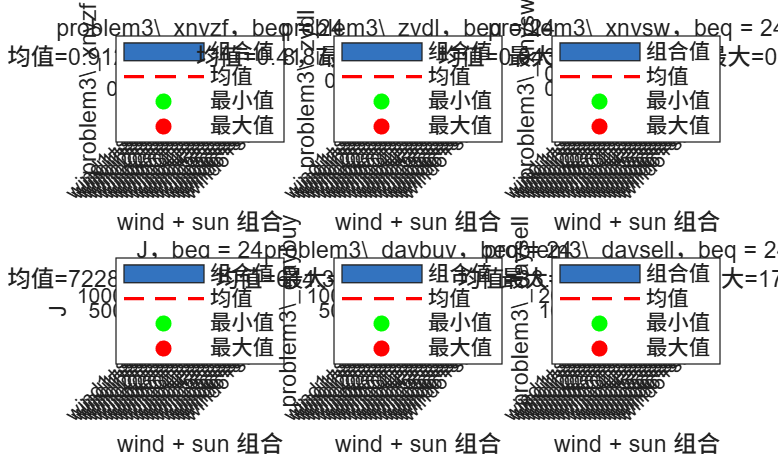

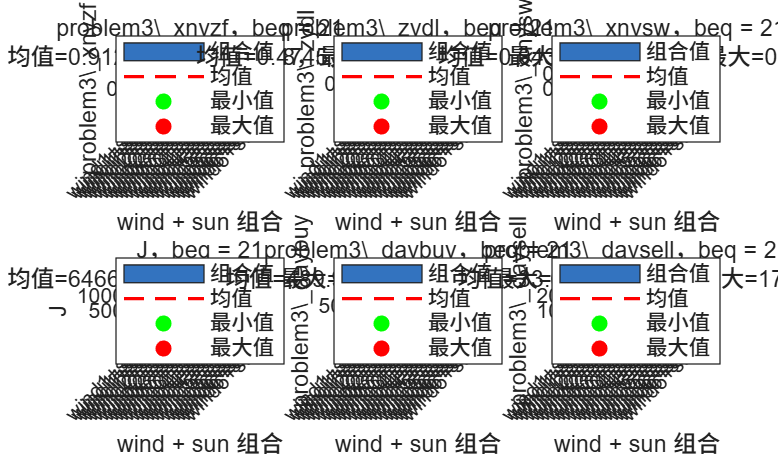

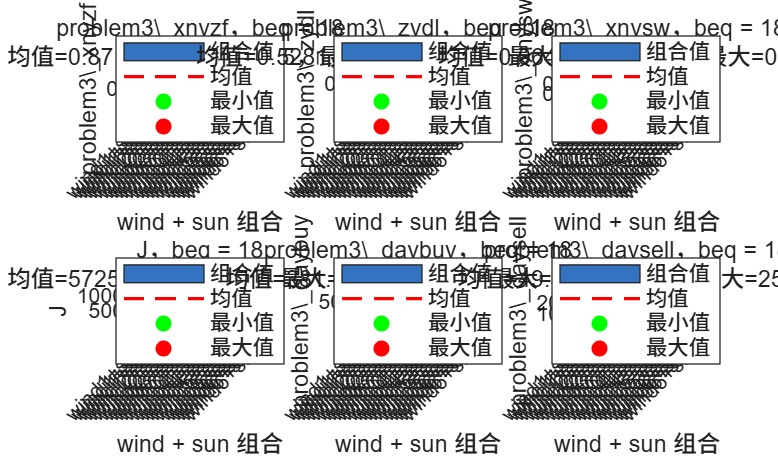

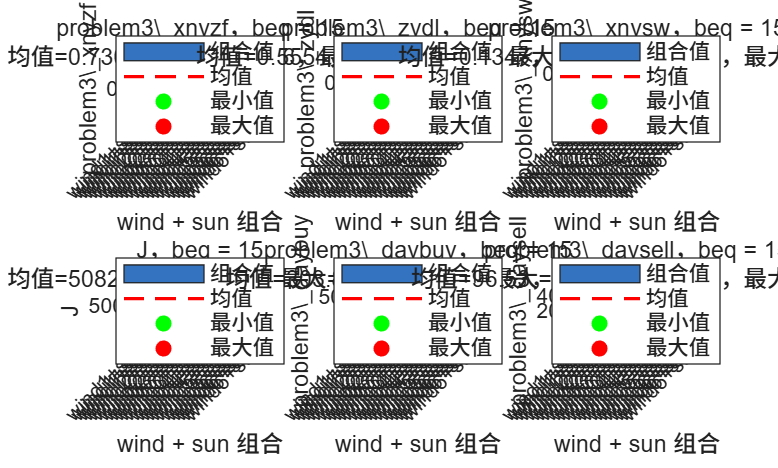

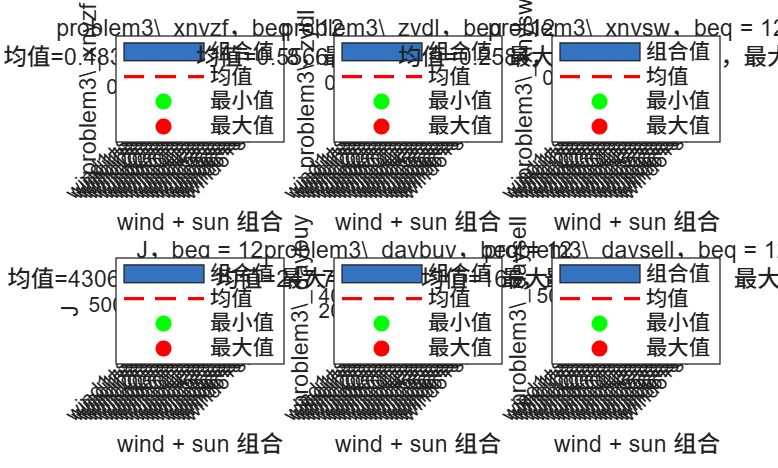


plotProblem3Distributions(problem3_results, beq_values);


function metrics = calcProblem3Metrics(t, classicload, wind, sun, fenshijijia)
    t = t(:);
    classicload = classicload(:);
    wind = wind(:);
    sun = sun(:);
    fenshijijia = fenshijijia(:);

    metrics.nh3load = t*20.75*2;
    metrics.load = classicload*6 + metrics.nh3load;
    metrics.generate = wind*40 + sun*64;
    metrics.buy = metrics.load - metrics.generate;
    metrics.sell = metrics.buy;
    metrics.buy(metrics.buy<0) = 0;
    metrics.sell(metrics.sell>0) = 0;
    metrics.buycost = sum(metrics.buy .* fenshijijia);
    metrics.dayload = sum(metrics.load);
    metrics.daygenerate = sum(metrics.generate);
    metrics.daybuy = sum(metrics.buy);
    metrics.daysell = abs(sum(metrics.sell));

    metrics.xnyzf = (metrics.dayload-metrics.daysell-metrics.daybuy)/metrics.daygenerate;
    metrics.zydl = (metrics.daygenerate-metrics.daysell)/metrics.dayload;
    metrics.xnysw = metrics.daysell/metrics.daygenerate;
end

function J = objFun(t, classicload, wind, sun, fenshijijia)
    t = t(:);
    classicload = classicload(:);
    wind = wind(:);
    sun = sun(:);
    fenshijijia = fenshijijia(:);

    problem3_nh3load = t*20.75*2;
    problem3_load = classicload*6 + problem3_nh3load;
    problem3_generate = wind*40 + sun*64;
    problem3_buy = problem3_load - problem3_generate;
    problem3_sell = problem3_buy;
    problem3_buy(problem3_buy<0) = 0;
    problem3_sell(problem3_sell>0) = 0;
    problem3_buycost = sum(problem3_buy .* fenshijijia);
    problem3_sellcost = sum(problem3_sell*377.9);
    problem3_cost =   problem3_sellcost + problem3_buycost ...
                  + 0.75*2*sum(t)*2 ...
                  + 1.5*2*1000*0.2*60000/365/30 ...
                  + 10*2*sum(t)*100 ...
                  + 10*2*sum(t)*150 ...
                  + sum(sun)*64*1000*0.12 ...
                  + sum(wind)*40*1000*0.15;
    J = problem3_cost / (sum(t)*3);
end

function plotProblem3Distributions(problem3_results, beq_values)
    metric_fields = {'xnyzf', 'zydl', 'xnysw', 'J_min', 'daybuy', 'daysell'};
    metric_names = {'problem3\_xnyzf', 'problem3\_zydl', 'problem3\_xnysw', ...
                    'J', 'problem3\_daybuy', 'problem3\_daysell'};

    for beq_idx = 1:numel(beq_values)
        beq = beq_values(beq_idx);
        beq_mask = [problem3_results.beq] == beq;
        beq_results = problem3_results(beq_mask);

        if isempty(beq_results)
            warning('beq = %g 没有可绘制的结果。', beq);
            continue;
        end

        sort_keys = [[beq_results.wind_idx]', [beq_results.sun_idx]'];
        [~, order] = sortrows(sort_keys, [1 2]);
        beq_results = beq_results(order);

        combo_labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), ...
                                beq_results, 'UniformOutput', false);

        figure('Name', sprintf('beq=%g 下 24 种 wind/sun 组合指标分布', beq), ...
               'Color', 'w');

        for metric_idx = 1:numel(metric_fields)
            metric_field = metric_fields{metric_idx};
            metric_name = metric_names{metric_idx};
            values = arrayfun(@(r) r.(metric_field), beq_results);

            subplot(2, 3, metric_idx);
            bar(values, 'FaceColor', [0.2 0.45 0.75]);
            grid on;
            hold on;

            valid_values = values(~isnan(values));
            mean_value = mean(valid_values);
            min_value = min(valid_values);
            max_value = max(valid_values);
            [~, min_idx] = min(values);
            [~, max_idx] = max(values);

            plot(xlim, [mean_value mean_value], 'r--', 'LineWidth', 1.2);
            scatter(min_idx, min_value, 45, 'g', 'filled');
            scatter(max_idx, max_value, 45, 'r', 'filled');

            title({sprintf('%s，beq = %g', metric_name, beq), ...
                   sprintf('均值=%.4g，最小=%.4g，最大=%.4g', ...
                           mean_value, min_value, max_value)}, ...
                  'Interpreter', 'none');
            xlabel('wind + sun 组合');
            ylabel(metric_name, 'Interpreter', 'none');
            set(gca, 'XTick', 1:numel(combo_labels), ...
                     'XTickLabel', combo_labels, ...
                     'XTickLabelRotation', 45);
            xlim([0.5, numel(combo_labels) + 0.5]);

            if min_value == max_value
                ylim([min_value - 0.5, max_value + 0.5]);
            end

            legend({'组合值', '均值', '最小值', '最大值'}, ...
                   'Location', 'best', 'FontSize', 8);
            hold off;
        end
    end
end

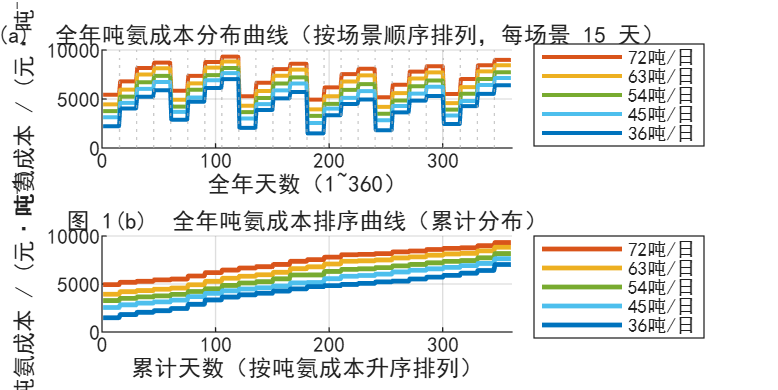

%% ============================================================
%  问题三(1)-(3) 绘图与分析补齐
%  前提：已经运行完前面的主循环，工作区中存在 problem3_results
%  以及 beq_values = [24, 21, 18, 15, 12]
%  ============================================================
%  作者建模约定：
%   - 24 风光场景，每场景代表 15 天，全年共 360 天
%   - 5 种产量方案：beq=24/21/18/15/12 对应 72/63/54/45/36 吨/日
%   - 吨氨成本 = J_min（元/吨）
%   - 绿电指标阈值：xnyzf>0.60, zydl>0.30, xnysw<0.20
%  ============================================================

%% 0. 公共设置
set(0, 'DefaultAxesFontName', 'SimHei');           % 中文字体
set(0, 'DefaultTextFontName', 'SimHei');
set(0, 'DefaultAxesFontSize', 10);

DAYS_PER_SCENARIO = 15;
N_SCENARIO        = 24;
N_DAY             = DAYS_PER_SCENARIO * N_SCENARIO;   % 360
beq_to_yield      = containers.Map([24 21 18 15 12], [72 63 54 45 36]);

% 绿电三指标阈值
TH_XNYZF = 0.60;
TH_ZYDL  = 0.30;
TH_XNYSW = 0.20;

% 把 problem3_results 整理成 (24场景 × 5产量) 的结构矩阵
% 行：场景索引（wind_idx-1)*4 + sun_idx，1~24
% 列：产量索引（beq=24 列1, beq=21 列2, ... beq=12 列5）
n_beq = numel(beq_values);
result_grid = cell(N_SCENARIO, n_beq);

for k = 1:numel(problem3_results)
    r = problem3_results(k);
    scen_idx = (r.wind_idx - 1) * 4 + r.sun_idx;
    [~, beq_col] = ismember(r.beq, beq_values);
    result_grid{scen_idx, beq_col} = r;
end

% 提取核心指标矩阵：24 行场景 × 5 列产量
J_mat      = zeros(N_SCENARIO, n_beq);   % 吨氨成本
xnyzf_mat  = zeros(N_SCENARIO, n_beq);
zydl_mat   = zeros(N_SCENARIO, n_beq);
xnysw_mat  = zeros(N_SCENARIO, n_beq);
buy_mat    = zeros(N_SCENARIO, n_beq);   % 日购电量
sell_mat   = zeros(N_SCENARIO, n_beq);   % 日上网电量
load_mat   = zeros(N_SCENARIO, n_beq);   % 日用电量
gen_mat    = zeros(N_SCENARIO, n_beq);   % 日发电量
scen_label = cell(N_SCENARIO, 1);

for s = 1:N_SCENARIO
    for b = 1:n_beq
        r = result_grid{s, b};
        J_mat(s, b)     = r.J_min;
        xnyzf_mat(s, b) = r.xnyzf;
        zydl_mat(s, b)  = r.zydl;
        xnysw_mat(s, b) = r.xnysw;
        buy_mat(s, b)   = r.daybuy;
        sell_mat(s, b)  = r.daysell;
        load_mat(s, b)  = r.dayload;
        gen_mat(s, b)   = r.daygenerate;
        if b == 1
            scen_label{s} = sprintf('%s+%s', r.wind_name, r.sun_name);
        end
    end
end

% 产量标签
yield_label = arrayfun(@(b) sprintf('%d吨/日', beq_to_yield(b)), beq_values, ...
                      'UniformOutput', false);

%% ============================================================
%  图 1：全年吨氨成本分布曲线（5 种产量并列）—— 必画
%  ============================================================
fig1 = figure('Name', '问题三(1) 全年吨氨成本分布曲线', ...
              'Color', 'w', 'Position', [100 100 1200 600]);

colors_5 = [0.85 0.33 0.10;    % 72 红
            0.93 0.69 0.13;    % 63 橙
            0.47 0.67 0.19;    % 54 绿
            0.30 0.75 0.93;    % 45 浅蓝
            0.00 0.45 0.74];   % 36 深蓝

% 构造 360 天全年序列（按场景顺序拼接，每场景重复 15 天）
day_axis = 1:N_DAY;
all_year_cost = zeros(N_DAY, n_beq);   % 360天 × 5产量

for b = 1:n_beq
    for s = 1:N_SCENARIO
        idx_start = (s - 1) * DAYS_PER_SCENARIO + 1;
        idx_end   = s * DAYS_PER_SCENARIO;
        all_year_cost(idx_start:idx_end, b) = J_mat(s, b);
    end
end

% --- 子图(a)：阶梯曲线（每场景 15 天一段水平台阶）
subplot(2, 1, 1);
hold on; grid on;
for b = 1:n_beq
    plot(day_axis, all_year_cost(:, b), '-', 'LineWidth', 1.5, ...
         'Color', colors_5(b, :), 'DisplayName', yield_label{b});
end
% 场景分界线
for s = 1:N_SCENARIO-1
    xline(s * DAYS_PER_SCENARIO + 0.5, ':', 'Color', [0.7 0.7 0.7], ...
          'HandleVisibility', 'off');
end
xlabel('全年天数（1~360）');
ylabel('吨氨成本 / (元·吨^{-1})');
title('图 1(a)  全年吨氨成本分布曲线（按场景顺序排列，每场景 15 天）');
legend('Location', 'eastoutside', 'NumColumns', 1);
xlim([0 N_DAY+1]);

% --- 子图(b)：吨氨成本排序曲线（按从小到大排序，更直观看分布）
subplot(2, 1, 2);
hold on; grid on;
for b = 1:n_beq
    sorted_cost = sort(all_year_cost(:, b), 'ascend');
    plot(day_axis, sorted_cost, '-', 'LineWidth', 1.8, ...
         'Color', colors_5(b, :), 'DisplayName', yield_label{b});
end
xlabel('累计天数（按吨氨成本升序排列）');
ylabel('吨氨成本 / (元·吨^{-1})');
title('图 1(b)  全年吨氨成本排序曲线（累计分布）');
legend('Location', 'eastoutside', 'NumColumns', 1);
xlim([0 N_DAY+1]);

% 保存
saveas(fig1, 'problem3_annual_cost_curve.png');

fprintf('\n[图 1] 已保存：problem3_annual_cost_curve.png\n');


[图 1] 已保存：problem3_annual_cost_curve.png


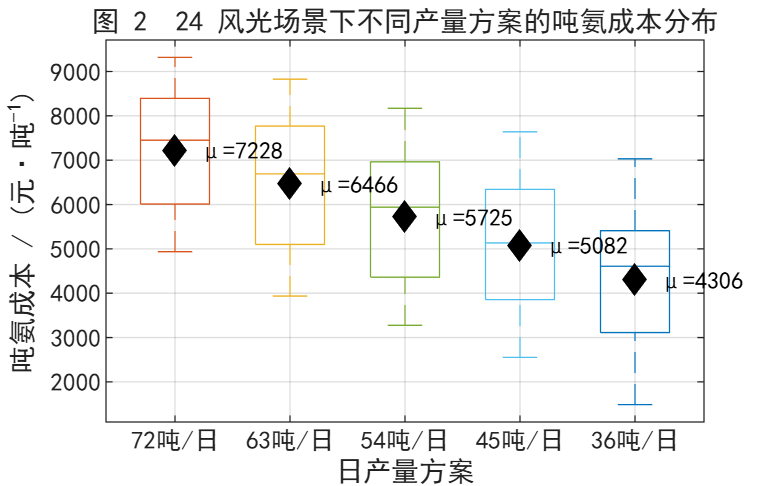


%% ============================================================
%  图 2：吨氨成本箱线图（5 种产量分布）
%  ============================================================
fig2 = figure('Name', '问题三(1) 吨氨成本箱线图', ...
              'Color', 'w', 'Position', [100 100 800 500]);

% 把 J_mat 展开成箱线图格式
boxplot(J_mat, 'Labels', yield_label, 'Colors', colors_5, 'Widths', 0.6);
grid on;
xlabel('日产量方案');
ylabel('吨氨成本 / (元·吨^{-1})');
title('图 2  24 风光场景下不同产量方案的吨氨成本分布');

% 在图上标注均值
hold on;
mean_J = mean(J_mat, 1);
plot(1:n_beq, mean_J, 'd', 'MarkerSize', 8, ...
     'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k');
for b = 1:n_beq
    text(b, mean_J(b), sprintf('  μ=%.0f', mean_J(b)), ...
         'FontSize', 9, 'Color', 'k');
end
saveas(fig2, 'problem3_cost_boxplot.png');

fprintf('[图 2] 已保存：problem3_cost_boxplot.png\n');

[图 2] 已保存：problem3_cost_boxplot.png


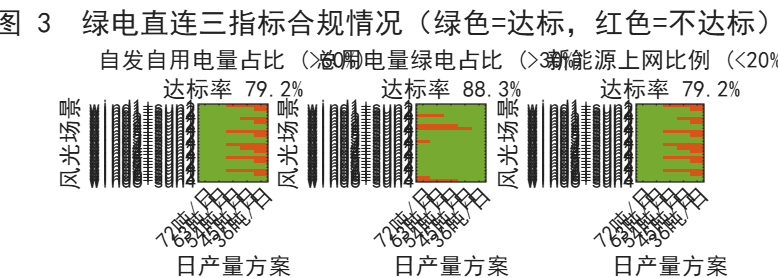


%% ============================================================
%  图 3：绿电三指标合规情况（24 场景 × 5 产量 热图）
%  ============================================================
fig3 = figure('Name', '问题三(1) 绿电指标合规热图', ...
              'Color', 'w', 'Position', [100 100 1400 500]);

% 三个指标分别判定是否达标
pass_xnyzf = xnyzf_mat > TH_XNYZF;        % 自发自用 > 60%
pass_zydl  = zydl_mat  > TH_ZYDL;          % 绿电占比 > 30%
pass_xnysw = xnysw_mat < TH_XNYSW;        % 上网比例 < 20%

% 三项全满足/部分满足/全不满足
pass_count = double(pass_xnyzf) + double(pass_zydl) + double(pass_xnysw);
% pass_count = 3 全满足；1~2 部分满足；0 全不满足

subplot(1, 3, 1);
imagesc(double(pass_xnyzf));
colormap(gca, [0.85 0.33 0.10; 0.47 0.67 0.19]);    % 红=不达标 绿=达标
caxis([0 1]);
title({'自发自用电量占比 (>60%)', sprintf('达标率 %.1f%%', 100*mean(pass_xnyzf(:)))});
xlabel('日产量方案'); ylabel('风光场景');
set(gca, 'XTick', 1:n_beq, 'XTickLabel', yield_label, ...
         'YTick', 1:N_SCENARIO, 'YTickLabel', scen_label, 'FontSize', 8);
xtickangle(45);

subplot(1, 3, 2);
imagesc(double(pass_zydl));
colormap(gca, [0.85 0.33 0.10; 0.47 0.67 0.19]);
caxis([0 1]);
title({'总用电量绿电占比 (>30%)', sprintf('达标率 %.1f%%', 100*mean(pass_zydl(:)))});
xlabel('日产量方案'); ylabel('风光场景');
set(gca, 'XTick', 1:n_beq, 'XTickLabel', yield_label, ...
         'YTick', 1:N_SCENARIO, 'YTickLabel', scen_label, 'FontSize', 8);
xtickangle(45);

subplot(1, 3, 3);
imagesc(double(pass_xnysw));
colormap(gca, [0.85 0.33 0.10; 0.47 0.67 0.19]);
caxis([0 1]);
title({'新能源上网比例 (<20%)', sprintf('达标率 %.1f%%', 100*mean(pass_xnysw(:)))});
xlabel('日产量方案'); ylabel('风光场景');
set(gca, 'XTick', 1:n_beq, 'XTickLabel', yield_label, ...
         'YTick', 1:N_SCENARIO, 'YTickLabel', scen_label, 'FontSize', 8);
xtickangle(45);

sgtitle('图 3  绿电直连三指标合规情况（绿色=达标，红色=不达标）');
saveas(fig3, 'problem3_compliance_heatmap.png');

fprintf('[图 3] 已保存：problem3_compliance_heatmap.png\n');

[图 3] 已保存：problem3_compliance_heatmap.png


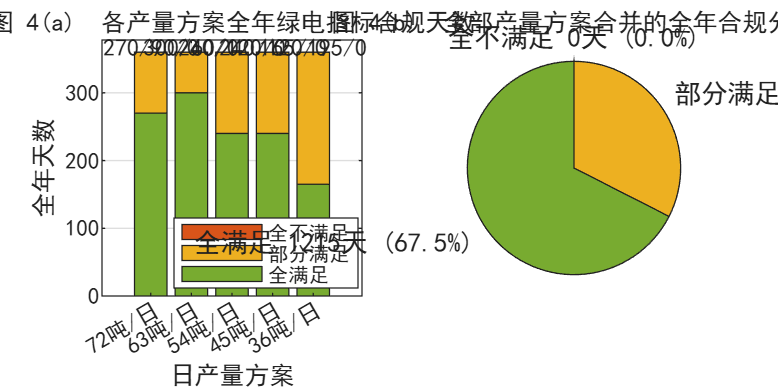


%% ============================================================
%  图 4：全满足/部分满足/全不满足分类统计（按产量）
%  ============================================================
fig4 = figure('Name', '问题三(1) 三类合规统计', ...
              'Color', 'w', 'Position', [100 100 1000 500]);

cat_all_pass   = (pass_count == 3);
cat_partial    = (pass_count >= 1) & (pass_count <= 2);
cat_none_pass  = (pass_count == 0);

% 按产量列统计天数（每场景=15天）
days_all    = sum(cat_all_pass,  1) * DAYS_PER_SCENARIO;
days_part   = sum(cat_partial,   1) * DAYS_PER_SCENARIO;
days_none   = sum(cat_none_pass, 1) * DAYS_PER_SCENARIO;

subplot(1, 2, 1);
bar_data = [days_all; days_part; days_none]';     % 5×3
b_h = bar(bar_data, 'stacked');
b_h(1).FaceColor = [0.47 0.67 0.19];   % 全满足 绿
b_h(2).FaceColor = [0.93 0.69 0.13];   % 部分满足 橙
b_h(3).FaceColor = [0.85 0.33 0.10];   % 全不满足 红
grid on;
xlabel('日产量方案'); ylabel('全年天数');
set(gca, 'XTickLabel', yield_label);
legend({'全满足', '部分满足', '全不满足'}, 'Location', 'best');
title('图 4(a)  各产量方案全年绿电指标合规天数');
ylim([0 N_DAY*1.05]);
% 在柱顶标注
for i = 1:n_beq
    text(i, N_DAY*1.02, sprintf('%d/%d/%d', days_all(i), days_part(i), days_none(i)), ...
         'HorizontalAlignment', 'center', 'FontSize', 9);
end

% 子图(b)：饼图——全部 5 种产量合并后的整体合规分布
subplot(1, 2, 2);
total_all  = sum(days_all);
total_part = sum(days_part);
total_none = sum(days_none);
pie_data = [total_all, total_part, total_none];
pie_labels = {sprintf('全满足 %d天 (%.1f%%)', total_all,  100*total_all /sum(pie_data)), ...
              sprintf('部分满足 %d天 (%.1f%%)', total_part, 100*total_part/sum(pie_data)), ...
              sprintf('全不满足 %d天 (%.1f%%)', total_none, 100*total_none/sum(pie_data))};
pie_h = pie(pie_data, pie_labels);
colormap_local = [0.47 0.67 0.19; 0.93 0.69 0.13; 0.85 0.33 0.10];
for i = 1:3
    pie_h(2*i-1).FaceColor = colormap_local(i, :);
end
title('图 4(b)  全部产量方案合并的全年合规分布');

saveas(fig4, 'problem3_compliance_summary.png');

fprintf('[图 4] 已保存：problem3_compliance_summary.png\n');

[图 4] 已保存：problem3_compliance_summary.png


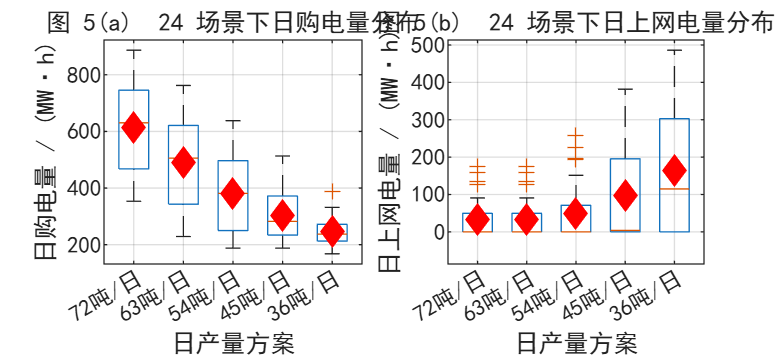


%% ============================================================
%  图 5：购售电量分布（按产量）
%  ============================================================
fig5 = figure('Name', '问题三(2) 购售电量分布', ...
              'Color', 'w', 'Position', [100 100 1200 500]);

subplot(1, 2, 1);
boxplot(buy_mat, 'Labels', yield_label, 'Widths', 0.6);
grid on;
xlabel('日产量方案'); ylabel('日购电量 / (MW·h)');
title('图 5(a)  24 场景下日购电量分布');
hold on;
plot(1:n_beq, mean(buy_mat, 1), 'rd', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

subplot(1, 2, 2);
boxplot(sell_mat, 'Labels', yield_label, 'Widths', 0.6);
grid on;
xlabel('日产量方案'); ylabel('日上网电量 / (MW·h)');
title('图 5(b)  24 场景下日上网电量分布');
hold on;
plot(1:n_beq, mean(sell_mat, 1), 'rd', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

saveas(fig5, 'problem3_buy_sell_distribution.png');

fprintf('[图 5] 已保存：problem3_buy_sell_distribution.png\n');

[图 5] 已保存：problem3_buy_sell_distribution.png


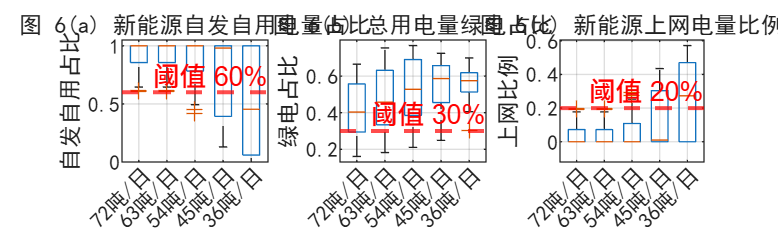


%% ============================================================
%  图 6：绿电三指标分布（按产量箱线图）—— 问题三(2)
%  ============================================================
fig6 = figure('Name', '问题三(2) 绿电指标分布', ...
              'Color', 'w', 'Position', [100 100 1500 450]);

subplot(1, 3, 1);
boxplot(xnyzf_mat, 'Labels', yield_label, 'Widths', 0.6);
yline(TH_XNYZF, 'r--', sprintf('阈值 %.0f%%', TH_XNYZF*100), 'LineWidth', 1.5);
grid on; ylabel('自发自用占比');
title('图 6(a) 新能源自发自用电量占比');
ylim([0 1.05]);

subplot(1, 3, 2);
boxplot(zydl_mat, 'Labels', yield_label, 'Widths', 0.6);
yline(TH_ZYDL, 'r--', sprintf('阈值 %.0f%%', TH_ZYDL*100), 'LineWidth', 1.5);
grid on; ylabel('绿电占比');
title('图 6(b) 总用电量绿电占比');

subplot(1, 3, 3);
boxplot(xnysw_mat, 'Labels', yield_label, 'Widths', 0.6);
yline(TH_XNYSW, 'r--', sprintf('阈值 %.0f%%', TH_XNYSW*100), 'LineWidth', 1.5);
grid on; ylabel('上网比例');
title('图 6(c) 新能源上网电量比例');

saveas(fig6, 'problem3_three_indicators.png');

fprintf('[图 6] 已保存：problem3_three_indicators.png\n');

[图 6] 已保存：problem3_three_indicators.png



%% ============================================================
%  数值统计 —— 控制台输出关键结论
%  ============================================================
fprintf('\n\n');
fprintf('=========================================================\n');

fprintf('              问题三 关键数值结论汇总                    \n');

              问题三 关键数值结论汇总                    


fprintf('=========================================================\n');


% 1) 各产量方案吨氨成本统计
fprintf('\n【1】各产量方案吨氨成本统计（元/吨）：\n');


【1】各产量方案吨氨成本统计（元/吨）：


fprintf('  %-10s  %-10s  %-10s  %-10s  %-10s  %-10s\n', ...
        '产量', '最小', '最大', '均值', '中位数', '标准差');

  产量          最小          最大          均值          中位数         标准差       


for b = 1:n_beq
    fprintf('  %-10s  %-10.2f  %-10.2f  %-10.2f  %-10.2f  %-10.2f\n', ...
            yield_label{b}, min(J_mat(:,b)), max(J_mat(:,b)), ...
            mean(J_mat(:,b)), median(J_mat(:,b)), std(J_mat(:,b)));
end

  72吨/日       4935.96     9318.91     7228.33     7450.73     1366.49   
  63吨/日       3936.28     8826.25     6465.75     6691.18     1524.07   
  54吨/日       3276.33     8169.36     5724.87     5940.01     1491.34   
  45吨/日       2552.54     7639.34     5082.27     5133.99     1498.17   
  36吨/日       1486.63     7031.67     4305.93     4607.55     1548.61   



% 2) 全年总吨氨成本（口径：全年总成本/全年总产量）
fprintf('\n【2】全年总吨氨成本（按产量方案分别核算）：\n');


【2】全年总吨氨成本（按产量方案分别核算）：


fprintf('  %-10s  %-15s  %-15s  %-15s\n', ...
        '产量', '全年总成本(元)', '全年总产氨(吨)', '全年吨氨成本(元/吨)');

  产量          全年总成本(元)         全年总产氨(吨)         全年吨氨成本(元/吨)    


total_cost_per_yield = zeros(1, n_beq);
total_ammonia_per_yield = zeros(1, n_beq);
annual_cost_per_yield = zeros(1, n_beq);
for b = 1:n_beq
    yield_b = beq_to_yield(beq_values(b));    % 该方案日产氨吨数
    % 每场景 15 天，对应该场景吨氨成本×日产量×15
    total_cost_per_yield(b)    = sum(J_mat(:, b) * yield_b * DAYS_PER_SCENARIO);
    total_ammonia_per_yield(b) = sum(yield_b * DAYS_PER_SCENARIO * ones(N_SCENARIO, 1));
    annual_cost_per_yield(b)   = total_cost_per_yield(b) / total_ammonia_per_yield(b);
    fprintf('  %-10s  %-15.2e  %-15.0f  %-15.2f\n', ...
            yield_label{b}, total_cost_per_yield(b), ...
            total_ammonia_per_yield(b), annual_cost_per_yield(b));
end

  72吨/日       1.87e+08         25920            7228.33        
  63吨/日       1.47e+08         22680            6465.75        
  54吨/日       1.11e+08         19440            5724.87        
  45吨/日       8.23e+07         16200            5082.27        
  36吨/日       5.58e+07         12960            4305.93        



[best_annual_cost, best_b] = min(annual_cost_per_yield);
fprintf('\n  ==> 全年综合最优产量方案：%s，全年吨氨成本 %.2f 元/吨\n', ...
        yield_label{best_b}, best_annual_cost);


  ==> 全年综合最优产量方案：36吨/日，全年吨氨成本 4305.93 元/吨



% 3) 绿电指标三类合规统计
fprintf('\n【3】绿电指标全年合规分布：\n');


【3】绿电指标全年合规分布：


fprintf('  %-10s  %-12s  %-12s  %-12s\n', ...
        '产量', '全满足(天)', '部分满足(天)', '全不满足(天)');

  产量          全满足(天)        部分满足(天)       全不满足(天)     


for b = 1:n_beq
    fprintf('  %-10s  %-12d  %-12d  %-12d\n', ...
            yield_label{b}, days_all(b), days_part(b), days_none(b));
end

  72吨/日       270           90            0           
  63吨/日       300           60            0           
  54吨/日       240           120           0           
  45吨/日       240           120           0           
  36吨/日       165           195           0           


fprintf('  %-10s  %-12d  %-12d  %-12d\n', ...
        '合计', sum(days_all), sum(days_part), sum(days_none));

  合计          1215          585           0           



% 4) 单指标达标率
fprintf('\n【4】单项指标达标情况（按产量）：\n');


【4】单项指标达标情况（按产量）：


fprintf('  %-10s  %-15s  %-15s  %-15s\n', ...
        '产量', '自发自用达标率', '绿电占比达标率', '上网比例达标率');

  产量          自发自用达标率          绿电占比达标率          上网比例达标率        


for b = 1:n_beq
    fprintf('  %-10s  %-15.1f%%  %-15.1f%%  %-15.1f%%\n', ...
            yield_label{b}, ...
            100*mean(pass_xnyzf(:, b)), ...
            100*mean(pass_zydl(:, b)), ...
            100*mean(pass_xnysw(:, b)));
end

  72吨/日       100.0          %  75.0           %  100.0          %
  63吨/日       100.0          %  83.3           %  100.0          %
  54吨/日       79.2           %  87.5           %  79.2           %
  45吨/日       70.8           %  95.8           %  70.8           %
  36吨/日       45.8           %  100.0          %  45.8           %



% 5) 购售电量统计
fprintf('\n【5】日购售电量统计（MW·h）：\n');


【5】日购售电量统计（MW·h）：


fprintf('  %-10s  %-12s  %-12s  %-12s  %-12s\n', ...
        '产量', '购电均值', '购电最大', '上网均值', '上网最大');

  产量          购电均值          购电最大          上网均值          上网最大        


for b = 1:n_beq
    fprintf('  %-10s  %-12.2f  %-12.2f  %-12.2f  %-12.2f\n', ...
            yield_label{b}, ...
            mean(buy_mat(:, b)), max(buy_mat(:, b)), ...
            mean(sell_mat(:, b)), max(sell_mat(:, b)));
end

  72吨/日       614.30        886.78        33.55         173.71      
  63吨/日       489.86        762.28        33.61         173.71      
  54吨/日       381.13        637.78        49.39         257.16      
  45吨/日       303.78        513.28        96.53         381.66      
  36吨/日       247.74        388.78        165.00        486.11      



% 6) 最优/最差场景识别
fprintf('\n【6】各产量方案下的最优/最差场景：\n');


【6】各产量方案下的最优/最差场景：


fprintf('  %-10s  %-25s  %-25s\n', '产量', '最低成本场景', '最高成本场景');

  产量          最低成本场景                     最高成本场景                   


for b = 1:n_beq
    [min_j, idx_min] = min(J_mat(:, b));
    [max_j, idx_max] = max(J_mat(:, b));
    fprintf('  %-10s  %-15s(%.0f)  %-15s(%.0f)\n', ...
            yield_label{b}, scen_label{idx_min}, min_j, ...
            scen_label{idx_max}, max_j);
end

  72吨/日       wind4+sun1     (4936)  wind2+sun4     (9319)
  63吨/日       wind4+sun1     (3936)  wind2+sun4     (8826)
  54吨/日       wind4+sun1     (3276)  wind2+sun4     (8169)
  45吨/日       wind4+sun1     (2553)  wind2+sun4     (7639)
  36吨/日       wind4+sun1     (1487)  wind2+sun4     (7032)



% 7) 综合最优产量及对应建议
fprintf('\n【7】综合建议：\n');


【7】综合建议：


[~, best_mean_b] = min(mean(J_mat, 1));
fprintf('   - 平均吨氨成本最低的产量方案：%s（均值 %.2f 元/吨）\n', ...
        yield_label{best_mean_b}, mean(J_mat(:, best_mean_b)));

   - 平均吨氨成本最低的产量方案：36吨/日（均值 4305.93 元/吨）


fprintf('   - 全年综合最优产量方案（按全年总成本核算）：%s（全年 %.2f 元/吨）\n', ...
        yield_label{best_b}, best_annual_cost);

   - 全年综合最优产量方案（按全年总成本核算）：36吨/日（全年 4305.93 元/吨）



% 是否所有方案都有部分不合规？
if all(days_none > 0) || all(days_part > 0)
    fprintf('   - ⚠️ 所有产量方案均存在绿电指标不完全合规的天数，\n');
    fprintf('     说明在仅依赖风光直连+电网交互的运行模式下，\n');
    fprintf('     难以在全部场景实现"自发自用>60%% + 上网<20%%"双重约束。\n');
end

   - ⚠️ 所有产量方案均存在绿电指标不完全合规的天数，


     说明在仅依赖风光直连+电网交互的运行模式下，


     难以在全部场景实现"自发自用>60% + 上网<20%"双重约束。



fprintf('\n=========================================================\n');

fprintf('  绘图与统计完成。所有图片已保存至当前工作目录。\n');

  绘图与统计完成。所有图片已保存至当前工作目录。


fprintf('=========================================================\n');


%% ============================================================
%  导出数据到 Excel 供论文表格使用
%  ============================================================
try
    % 构造 24×5 矩阵导出
    out_J = array2table(J_mat, 'VariableNames', ...
        {'Y72', 'Y63', 'Y54', 'Y45', 'Y36'}, ...
        'RowNames', scen_label);
    writetable(out_J, 'problem3_summary.xlsx', 'Sheet', '吨氨成本', ...
               'WriteRowNames', true);

    out_xnyzf = array2table(xnyzf_mat, 'VariableNames', ...
        {'Y72', 'Y63', 'Y54', 'Y45', 'Y36'}, 'RowNames', scen_label);
    writetable(out_xnyzf, 'problem3_summary.xlsx', 'Sheet', '自发自用', ...
               'WriteRowNames', true);

    out_zydl = array2table(zydl_mat, 'VariableNames', ...
        {'Y72', 'Y63', 'Y54', 'Y45', 'Y36'}, 'RowNames', scen_label);
    writetable(out_zydl, 'problem3_summary.xlsx', 'Sheet', '绿电占比', ...
               'WriteRowNames', true);

    out_xnysw = array2table(xnysw_mat, 'VariableNames', ...
        {'Y72', 'Y63', 'Y54', 'Y45', 'Y36'}, 'RowNames', scen_label);
    writetable(out_xnysw, 'problem3_summary.xlsx', 'Sheet', '上网比例', ...
               'WriteRowNames', true);

    fprintf('\n数据已导出：problem3_summary.xlsx\n');
catch ME
    warning('Excel 导出失败：%s（图片均已成功保存）', ME.message);
end


数据已导出：problem3_summary.xlsx


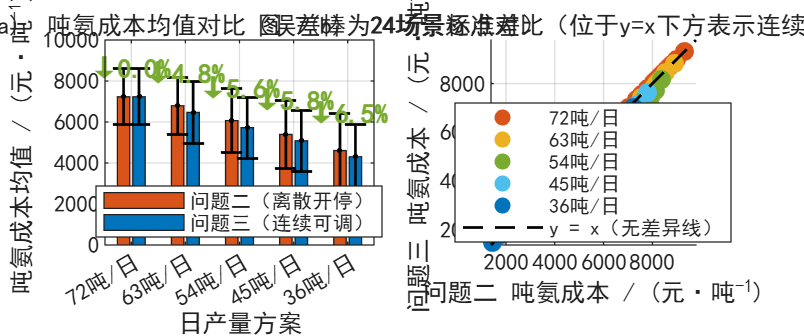

%% ============================================================
%  问题三(3)：问题二(离散开停) vs 问题三(连续可调) 对比分析
%  前提：工作区中同时存在 problem2_results 和 problem3_results
%       且二者都是 24 场景 × 5 产量 = 120 个元素的结构数组
%  ============================================================

%% 0. 公共设置
set(0, 'DefaultAxesFontName', 'SimHei');
set(0, 'DefaultTextFontName', 'SimHei');
set(0, 'DefaultAxesFontSize', 10);

DAYS_PER_SCENARIO = 15;
N_SCENARIO        = 24;
N_DAY             = DAYS_PER_SCENARIO * N_SCENARIO;
beq_values_local  = [24, 21, 18, 15, 12];
beq_to_yield      = containers.Map([24 21 18 15 12], [72 63 54 45 36]);
n_beq             = numel(beq_values_local);

% 绿电三指标阈值
TH_XNYZF = 0.60;
TH_ZYDL  = 0.30;
TH_XNYSW = 0.20;

yield_label = arrayfun(@(b) sprintf('%d吨/日', beq_to_yield(b)), beq_values_local, ...
                      'UniformOutput', false);

%% 1. 把两套 results 整理成 24×5 矩阵
[J2,  xnyzf2, zydl2, xnysw2, buy2, sell2, scen_label] = extractMat(problem2_results, beq_values_local);
[J3,  xnyzf3, zydl3, xnysw3, buy3, sell3, ~]          = extractMat(problem3_results, beq_values_local);

% 差值矩阵：连续 - 离散
dJ      = J3      - J2;       % 负值表示连续可调更省钱
dXnyzf  = xnyzf3  - xnyzf2;
dZydl   = zydl3   - zydl2;
dXnysw  = xnysw3  - xnysw2;
dBuy    = buy3    - buy2;
dSell   = sell3   - sell2;

%% ============================================================
%  图 7：吨氨成本对比（按产量分组的均值柱+误差棒）
%  ============================================================
fig7 = figure('Name', '问题三(3) 吨氨成本对比', ...
              'Color', 'w', 'Position', [100 100 1200 500]);

% --- 子图(a) 均值柱状对比
subplot(1, 2, 1);
mean_J2 = mean(J2, 1);
mean_J3 = mean(J3, 1);
std_J2  = std(J2, 0, 1);
std_J3  = std(J3, 0, 1);

bar_data = [mean_J2; mean_J3]';   % 5×2
b_h = bar(bar_data, 'grouped');
b_h(1).FaceColor = [0.85 0.33 0.10];   % 问题二 红
b_h(2).FaceColor = [0.00 0.45 0.74];   % 问题三 蓝
hold on; grid on;

% 误差棒
ngroups = n_beq;
nbars   = 2;
groupwidth = min(0.8, nbars/(nbars+1.5));
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    if i == 1
        errorbar(x, mean_J2, std_J2, 'k.', 'LineWidth', 1, 'CapSize', 8);
    else
        errorbar(x, mean_J3, std_J3, 'k.', 'LineWidth', 1, 'CapSize', 8);
    end
end

set(gca, 'XTickLabel', yield_label);
xlabel('日产量方案'); ylabel('吨氨成本均值 / (元·吨^{-1})');
legend({'问题二（离散开停）', '问题三（连续可调）'}, 'Location', 'best');
title('图 7(a)  吨氨成本均值对比（误差棒为24场景标准差）');

% 在柱顶标注下降幅度
for i = 1:n_beq
    drop_pct = (mean_J2(i) - mean_J3(i)) / mean_J2(i) * 100;
    text(i, max(mean_J2(i), mean_J3(i)) + max(std_J2(i), std_J3(i)) + 50, ...
         sprintf('↓%.1f%%', drop_pct), ...
         'HorizontalAlignment', 'center', 'FontSize', 10, ...
         'Color', [0.47 0.67 0.19], 'FontWeight', 'bold');
end

% --- 子图(b) 24场景散点对比
subplot(1, 2, 2);
hold on; grid on;
colors_5 = [0.85 0.33 0.10; 0.93 0.69 0.13; 0.47 0.67 0.19; ...
            0.30 0.75 0.93; 0.00 0.45 0.74];
for b = 1:n_beq
    scatter(J2(:, b), J3(:, b), 50, colors_5(b, :), 'filled', ...
            'DisplayName', yield_label{b});
end

% y=x 参考线
all_J = [J2(:); J3(:)];
lim_min = min(all_J) * 0.95;
lim_max = max(all_J) * 1.05;
plot([lim_min lim_max], [lim_min lim_max], 'k--', 'LineWidth', 1, ...
     'DisplayName', 'y = x（无差异线）');

xlabel('问题二 吨氨成本 / (元·吨^{-1})');
ylabel('问题三 吨氨成本 / (元·吨^{-1})');
title('图 7(b)  24场景逐点对比（位于y=x下方表示连续可调更优）');
legend('Location', 'best');
xlim([lim_min lim_max]); ylim([lim_min lim_max]);
axis square;

saveas(fig7, 'problem2vs3_cost_compare.png');

fprintf('[图 7] 已保存：problem2vs3_cost_compare.png\n');

[图 7] 已保存：problem2vs3_cost_compare.png


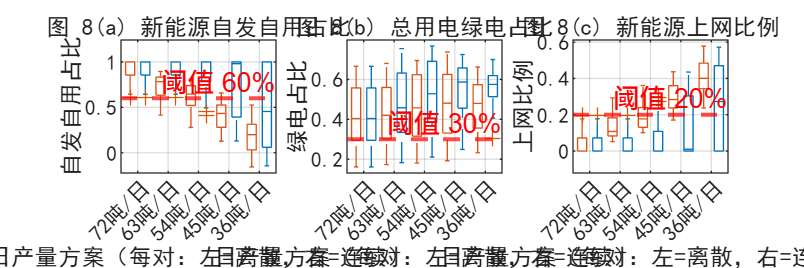


%% ============================================================
%  图 8：绿电三指标对比（箱线图并列）
%  ============================================================
fig8 = figure('Name', '问题三(3) 绿电指标对比', ...
              'Color', 'w', 'Position', [100 100 1500 500]);

% 把数据组织成 box plot 输入：每个产量两组（问题二、问题三）
plot_three_indicator_compare(1, xnyzf2, xnyzf3, yield_label, TH_XNYZF, ...
                              '图 8(a) 新能源自发自用占比', '自发自用占比');
plot_three_indicator_compare(2, zydl2, zydl3, yield_label, TH_ZYDL, ...
                              '图 8(b) 总用电绿电占比', '绿电占比');
plot_three_indicator_compare(3, xnysw2, xnysw3, yield_label, TH_XNYSW, ...
                              '图 8(c) 新能源上网比例', '上网比例');

saveas(fig8, 'problem2vs3_indicators_compare.png');

fprintf('[图 8] 已保存：problem2vs3_indicators_compare.png\n');

[图 8] 已保存：problem2vs3_indicators_compare.png


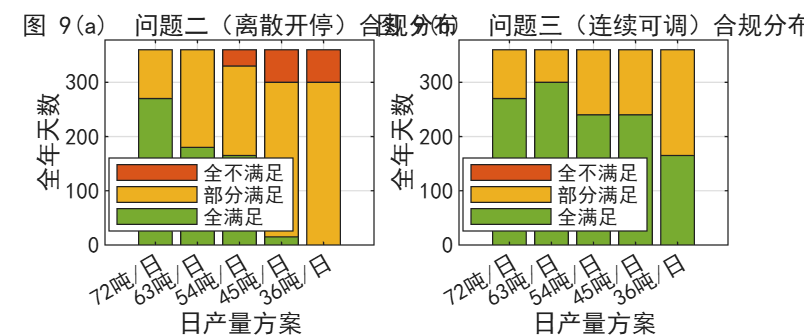


%% ============================================================
%  图 9：合规天数对比（堆叠柱）
%  ============================================================
fig9 = figure('Name', '问题三(3) 合规天数对比', ...
              'Color', 'w', 'Position', [100 100 1200 500]);

% 计算两套方案的合规分类
[days_all_p2, days_part_p2, days_none_p2] = countCompliance( ...
    xnyzf2, zydl2, xnysw2, TH_XNYZF, TH_ZYDL, TH_XNYSW, DAYS_PER_SCENARIO);
[days_all_p3, days_part_p3, days_none_p3] = countCompliance( ...
    xnyzf3, zydl3, xnysw3, TH_XNYZF, TH_ZYDL, TH_XNYSW, DAYS_PER_SCENARIO);

% --- 子图(a) 离散开停
subplot(1, 2, 1);
bar_data = [days_all_p2; days_part_p2; days_none_p2]';
b_h = bar(bar_data, 'stacked');
b_h(1).FaceColor = [0.47 0.67 0.19];
b_h(2).FaceColor = [0.93 0.69 0.13];
b_h(3).FaceColor = [0.85 0.33 0.10];
grid on;
xlabel('日产量方案'); ylabel('全年天数');
set(gca, 'XTickLabel', yield_label);
legend({'全满足', '部分满足', '全不满足'}, 'Location', 'best');
title('图 9(a)  问题二（离散开停）合规分布');
ylim([0 N_DAY*1.05]);

% --- 子图(b) 连续可调
subplot(1, 2, 2);
bar_data = [days_all_p3; days_part_p3; days_none_p3]';
b_h = bar(bar_data, 'stacked');
b_h(1).FaceColor = [0.47 0.67 0.19];
b_h(2).FaceColor = [0.93 0.69 0.13];
b_h(3).FaceColor = [0.85 0.33 0.10];
grid on;
xlabel('日产量方案'); ylabel('全年天数');
set(gca, 'XTickLabel', yield_label);
legend({'全满足', '部分满足', '全不满足'}, 'Location', 'best');
title('图 9(b)  问题三（连续可调）合规分布');
ylim([0 N_DAY*1.05]);

saveas(fig9, 'problem2vs3_compliance_compare.png');

fprintf('[图 9] 已保存：problem2vs3_compliance_compare.png\n');

[图 9] 已保存：problem2vs3_compliance_compare.png


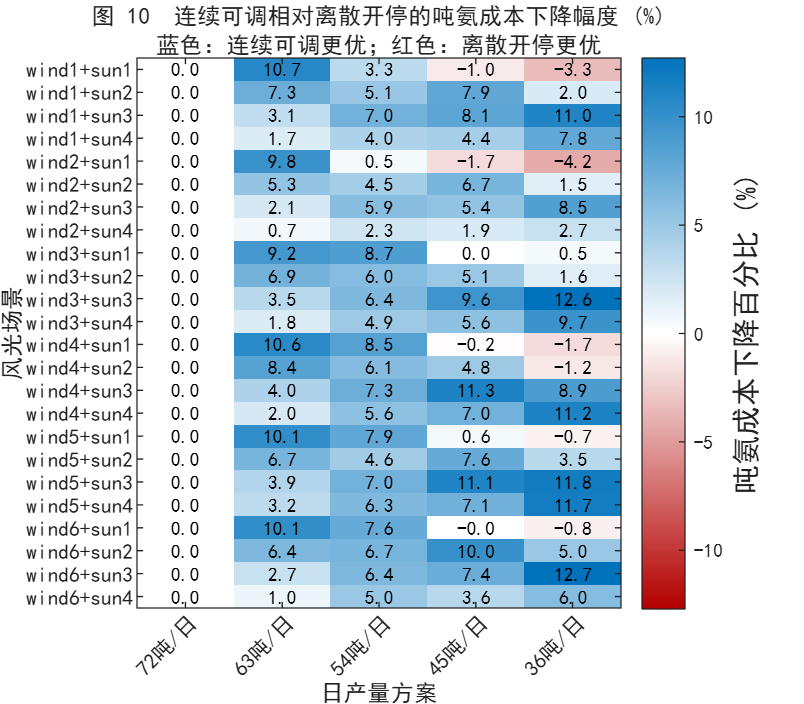


%% ============================================================
%  图 10：连续可调相比离散开停的"成本下降幅度"热图
%  ============================================================
fig10 = figure('Name', '问题三(3) 成本下降热图', ...
              'Color', 'w', 'Position', [100 100 800 700]);

% 计算每场景每产量的相对下降百分比
dJ_pct = (J2 - J3) ./ J2 * 100;   % 正值表示连续可调更省钱

imagesc(dJ_pct);
colormap(redblueColormap());
% 让 0 居中（白色），正值（连续更省）偏蓝，负值（离散更省，理论上不该出现）偏红
caxis_max = max(abs(dJ_pct(:)));
caxis([-caxis_max, caxis_max]);
cb = colorbar;
cb.Label.String = '吨氨成本下降百分比 (%)';
cb.Label.FontSize = 11;

% 数值标注
for s = 1:N_SCENARIO
    for b = 1:n_beq
        text(b, s, sprintf('%.1f', dJ_pct(s, b)), ...
             'HorizontalAlignment', 'center', 'FontSize', 7, ...
             'Color', 'k');
    end
end

xlabel('日产量方案'); ylabel('风光场景');
set(gca, 'XTick', 1:n_beq, 'XTickLabel', yield_label, ...
         'YTick', 1:N_SCENARIO, 'YTickLabel', scen_label, 'FontSize', 8);
xtickangle(45);
title({'图 10  连续可调相对离散开停的吨氨成本下降幅度 (%)', ...
       '蓝色：连续可调更优；红色：离散开停更优'});

saveas(fig10, 'problem2vs3_cost_drop_heatmap.png');

fprintf('[图 10] 已保存：problem2vs3_cost_drop_heatmap.png\n');

[图 10] 已保存：problem2vs3_cost_drop_heatmap.png


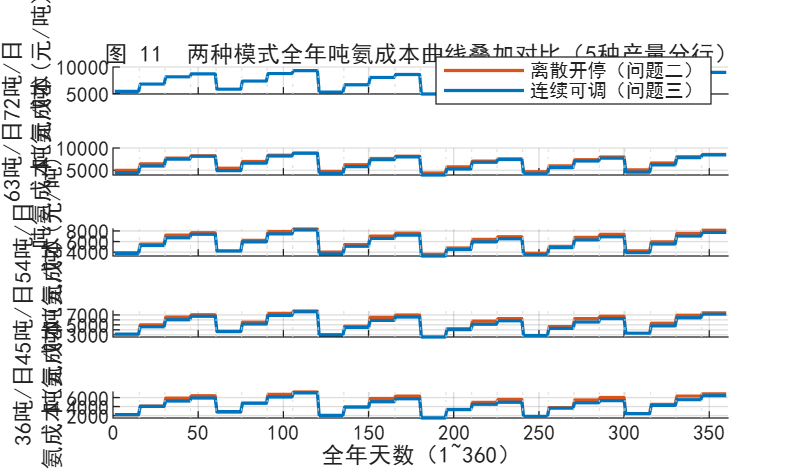


%% ============================================================
%  图 11：全年吨氨成本曲线叠加对比
%  ============================================================
fig11 = figure('Name', '问题三(3) 全年成本曲线对比', ...
              'Color', 'w', 'Position', [100 100 1200 700]);

day_axis = 1:N_DAY;

for b = 1:n_beq
    subplot(n_beq, 1, b);
    hold on; grid on;
    
    cost_p2 = zeros(N_DAY, 1);
    cost_p3 = zeros(N_DAY, 1);
    for s = 1:N_SCENARIO
        idx_start = (s - 1) * DAYS_PER_SCENARIO + 1;
        idx_end   = s * DAYS_PER_SCENARIO;
        cost_p2(idx_start:idx_end) = J2(s, b);
        cost_p3(idx_start:idx_end) = J3(s, b);
    end
    
    plot(day_axis, cost_p2, '-', 'LineWidth', 1.2, ...
         'Color', [0.85 0.33 0.10], 'DisplayName', '离散开停（问题二）');
    plot(day_axis, cost_p3, '-', 'LineWidth', 1.2, ...
         'Color', [0.00 0.45 0.74], 'DisplayName', '连续可调（问题三）');
    
    % 场景分界线
    for s = 1:N_SCENARIO-1
        xline(s * DAYS_PER_SCENARIO + 0.5, ':', 'Color', [0.85 0.85 0.85], ...
              'HandleVisibility', 'off');
    end
    
    ylabel(sprintf('%s\n吨氨成本(元/吨)', yield_label{b}));
    if b == 1
        title('图 11  两种模式全年吨氨成本曲线叠加对比（5种产量分行）');
        legend('Location', 'best');
    end
    if b == n_beq
        xlabel('全年天数（1~360）');
    else
        set(gca, 'XTickLabel', []);
    end
    xlim([0 N_DAY+1]);
end

saveas(fig11, 'problem2vs3_annual_curve_compare.png');

fprintf('[图 11] 已保存：problem2vs3_annual_curve_compare.png\n');

[图 11] 已保存：problem2vs3_annual_curve_compare.png



%% ============================================================
%  控制台数值结论
%  ============================================================
fprintf('\n\n');
fprintf('=========================================================\n');

fprintf('       问题三(3) 连续可调 vs 离散开停 对比结论          \n');

       问题三(3) 连续可调 vs 离散开停 对比结论          


fprintf('=========================================================\n');


% 1) 吨氨成本对比
fprintf('\n【1】吨氨成本对比（按产量分组，单位：元/吨）：\n');


【1】吨氨成本对比（按产量分组，单位：元/吨）：


fprintf('  %-10s  %-12s  %-12s  %-12s  %-10s\n', ...
        '产量', '问题二均值', '问题三均值', '下降值', '下降幅度');

  产量          问题二均值         问题三均值         下降值           下降幅度      


for b = 1:n_beq
    drop_abs = mean_J2(b) - mean_J3(b);
    drop_pct = drop_abs / mean_J2(b) * 100;
    fprintf('  %-10s  %-12.2f  %-12.2f  %-12.2f  %-10.2f%%\n', ...
            yield_label{b}, mean_J2(b), mean_J3(b), drop_abs, drop_pct);
end

  72吨/日       7228.33       7228.33       0.00          0.00      %
  63吨/日       6792.96       6465.75       327.21        4.82      %
  54吨/日       6066.77       5724.87       341.89        5.64      %
  45吨/日       5392.53       5082.27       310.26        5.75      %
  36吨/日       4604.89       4305.93       298.96        6.49      %



% 2) 全年总吨氨成本对比
fprintf('\n【2】全年总吨氨成本对比：\n');


【2】全年总吨氨成本对比：


fprintf('  %-10s  %-15s  %-15s  %-12s\n', ...
        '产量', '问题二(元/吨)', '问题三(元/吨)', '下降幅度');

  产量          问题二(元/吨)         问题三(元/吨)         下降幅度        


for b = 1:n_beq
    yield_b = beq_to_yield(beq_values_local(b));
    tot_p2 = sum(J2(:, b) * yield_b * DAYS_PER_SCENARIO) / ...
             (yield_b * DAYS_PER_SCENARIO * N_SCENARIO);
    tot_p3 = sum(J3(:, b) * yield_b * DAYS_PER_SCENARIO) / ...
             (yield_b * DAYS_PER_SCENARIO * N_SCENARIO);
    fprintf('  %-10s  %-15.2f  %-15.2f  %-12.2f%%\n', ...
            yield_label{b}, tot_p2, tot_p3, (tot_p2 - tot_p3) / tot_p2 * 100);
end

  72吨/日       7228.33          7228.33          0.00        %
  63吨/日       6792.96          6465.75          4.82        %
  54吨/日       6066.77          5724.87          5.64        %
  45吨/日       5392.53          5082.27          5.75        %
  36吨/日       4604.89          4305.93          6.49        %



% 3) 绿电指标变化
fprintf('\n【3】绿电三指标均值变化（连续 - 离散）：\n');


【3】绿电三指标均值变化（连续 - 离散）：


fprintf('  %-10s  %-15s  %-15s  %-15s\n', ...
        '产量', 'Δ自发自用', 'Δ绿电占比', 'Δ上网比例');

  产量          Δ自发自用            Δ绿电占比            Δ上网比例          


for b = 1:n_beq
    fprintf('  %-10s  %-15.4f  %-15.4f  %-15.4f\n', ...
            yield_label{b}, ...
            mean(dXnyzf(:, b)), mean(dZydl(:, b)), mean(dXnysw(:, b)));
end

  72吨/日       0.0000           0.0000           0.0000         
  63吨/日       0.1857           0.0486           -0.0929        
  54吨/日       0.2703           0.0689           -0.1352        
  45吨/日       0.3296           0.0813           -0.1648        
  36吨/日       0.3120           0.0888           -0.1560        



% 4) 合规天数变化
fprintf('\n【4】全年合规天数对比（全满足/部分满足/全不满足）：\n');


【4】全年合规天数对比（全满足/部分满足/全不满足）：


fprintf('  %-10s  %-25s  %-25s\n', '产量', '问题二（离散）', '问题三（连续）');

  产量          问题二（离散）                    问题三（连续）                  


for b = 1:n_beq
    fprintf('  %-10s  %3d / %3d / %3d %10s %3d / %3d / %3d\n', ...
            yield_label{b}, ...
            days_all_p2(b), days_part_p2(b), days_none_p2(b), '', ...
            days_all_p3(b), days_part_p3(b), days_none_p3(b));
end

  72吨/日       270 /  90 /   0            270 /  90 /   0
  63吨/日       180 / 180 /   0            300 /  60 /   0
  54吨/日       165 / 165 /  30            240 / 120 /   0
  45吨/日        15 / 285 /  60            240 / 120 /   0
  36吨/日         0 / 300 /  60            165 / 195 /   0


fprintf('  %-10s  %3d / %3d / %3d %10s %3d / %3d / %3d\n', ...
        '合计', ...
        sum(days_all_p2), sum(days_part_p2), sum(days_none_p2), '', ...
        sum(days_all_p3), sum(days_part_p3), sum(days_none_p3));

  合计          630 / 1020 / 150            1215 / 585 /   0



% 5) 购售电量变化
fprintf('\n【5】日购售电量变化（均值，连续 - 离散）：\n');


【5】日购售电量变化（均值，连续 - 离散）：


fprintf('  %-10s  %-15s  %-15s\n', '产量', 'Δ购电(MW·h)', 'Δ上网(MW·h)');

  产量          Δ购电(MW·h)        Δ上网(MW·h)      


for b = 1:n_beq
    fprintf('  %-10s  %-15.3f  %-15.3f\n', ...
            yield_label{b}, mean(dBuy(:, b)), mean(dSell(:, b)));
end

  72吨/日       0.000            0.000          
  63吨/日       -45.314          -45.314        
  54吨/日       -55.682          -55.682        
  45吨/日       -55.533          -55.533        
  36吨/日       -49.618          -49.618        



% 6) 关键结论
fprintf('\n【6】综合结论：\n');


【6】综合结论：


total_drop_pct = (mean(J2(:)) - mean(J3(:))) / mean(J2(:)) * 100;
fprintf('   - 连续可调相对离散开停，整体吨氨成本平均下降 %.2f%%。\n', total_drop_pct);

   - 连续可调相对离散开停，整体吨氨成本平均下降 4.25%。



[~, best_drop_b] = max(mean_J2 - mean_J3);
fprintf('   - 受益最大的产量方案：%s（绝对下降 %.2f 元/吨）。\n', ...
        yield_label{best_drop_b}, mean_J2(best_drop_b) - mean_J3(best_drop_b));

   - 受益最大的产量方案：54吨/日（绝对下降 341.89 元/吨）。



compliance_imp_all  = sum(days_all_p3)  - sum(days_all_p2);
compliance_imp_none = sum(days_none_p2) - sum(days_none_p3);
fprintf('   - 全年"全满足"天数增加 %d 天，"全不满足"天数减少 %d 天。\n', ...
        compliance_imp_all, compliance_imp_none);

   - 全年"全满足"天数增加 585 天，"全不满足"天数减少 150 天。



if mean(dSell(:)) < 0
    fprintf('   - 上网电量平均减少 %.2f MW·h/日，说明连续调节提升了新能源就地消纳能力。\n', ...
            -mean(dSell(:)));
end

   - 上网电量平均减少 41.23 MW·h/日，说明连续调节提升了新能源就地消纳能力。


if mean(dBuy(:)) < 0
    fprintf('   - 购电量平均减少 %.2f MW·h/日，说明连续调节优化了电网交互。\n', ...
            -mean(dBuy(:)));
end

   - 购电量平均减少 41.23 MW·h/日，说明连续调节优化了电网交互。



fprintf('\n=========================================================\n');

fprintf('  问题二 vs 问题三 对比完成。共生成 5 张对比图。\n');

  问题二 vs 问题三 对比完成。共生成 5 张对比图。


fprintf('=========================================================\n');


%% ============================================================
%  辅助函数
%  ============================================================
function [J_mat, xnyzf_mat, zydl_mat, xnysw_mat, buy_mat, sell_mat, scen_label] = ...
         extractMat(results, beq_values_local)
    % 把 results 结构数组整理成 24×5 矩阵
    N_SCENARIO = 24;
    n_beq = numel(beq_values_local);
    J_mat     = zeros(N_SCENARIO, n_beq);
    xnyzf_mat = zeros(N_SCENARIO, n_beq);
    zydl_mat  = zeros(N_SCENARIO, n_beq);
    xnysw_mat = zeros(N_SCENARIO, n_beq);
    buy_mat   = zeros(N_SCENARIO, n_beq);
    sell_mat  = zeros(N_SCENARIO, n_beq);
    scen_label = cell(N_SCENARIO, 1);

    for k = 1:numel(results)
        r = results(k);
        scen_idx = (r.wind_idx - 1) * 4 + r.sun_idx;
        [~, beq_col] = ismember(r.beq, beq_values_local);
        J_mat(scen_idx, beq_col)     = r.J_min;
        xnyzf_mat(scen_idx, beq_col) = r.xnyzf;
        zydl_mat(scen_idx, beq_col)  = r.zydl;
        xnysw_mat(scen_idx, beq_col) = r.xnysw;
        buy_mat(scen_idx, beq_col)   = r.daybuy;
        sell_mat(scen_idx, beq_col)  = r.daysell;
        if beq_col == 1
            scen_label{scen_idx} = sprintf('%s+%s', r.wind_name, r.sun_name);
        end
    end
end

function plot_three_indicator_compare(sub_idx, mat2, mat3, yield_label, threshold, ...
                                      ttl, ylbl)
    subplot(1, 3, sub_idx);
    n_beq = size(mat2, 2);
    % 把两组数据穿插放置：列 1,2 是产量1的两个组，列 3,4 是产量2的...
    plot_data = [];
    plot_group = [];
    color_grp = [];
    for b = 1:n_beq
        plot_data  = [plot_data;  mat2(:, b); mat3(:, b)];
        plot_group = [plot_group; (2*b-1)*ones(size(mat2,1),1); 2*b*ones(size(mat3,1),1)];
        color_grp  = [color_grp;  ones(size(mat2,1),1);          2*ones(size(mat3,1),1)];
    end
    
    % 用 boxplot 画并列箱线图
    positions = 1:(2*n_beq);
    boxplot(plot_data, plot_group, 'Positions', positions, 'Widths', 0.6, ...
            'Colors', repmat([0.85 0.33 0.10; 0.00 0.45 0.74], n_beq, 1));
    
    yline(threshold, 'r--', sprintf('阈值 %.0f%%', threshold*100), ...
          'LineWidth', 1.5);
    grid on;
    
    % x 轴标签放在每对箱子中间
    tick_pos = 1.5:2:(2*n_beq);
    set(gca, 'XTick', tick_pos, 'XTickLabel', yield_label);
    xlabel('日产量方案（每对：左=离散，右=连续）');
    ylabel(ylbl);
    title(ttl);
end

function [days_all, days_part, days_none] = countCompliance( ...
         xnyzf_mat, zydl_mat, xnysw_mat, TH_XNYZF, TH_ZYDL, TH_XNYSW, ...
         DAYS_PER_SCENARIO)
    pass_xnyzf = xnyzf_mat > TH_XNYZF;
    pass_zydl  = zydl_mat  > TH_ZYDL;
    pass_xnysw = xnysw_mat < TH_XNYSW;
    pass_count = double(pass_xnyzf) + double(pass_zydl) + double(pass_xnysw);
    
    cat_all_pass   = (pass_count == 3);
    cat_partial    = (pass_count >= 1) & (pass_count <= 2);
    cat_none_pass  = (pass_count == 0);
    
    days_all  = sum(cat_all_pass,  1) * DAYS_PER_SCENARIO;
    days_part = sum(cat_partial,   1) * DAYS_PER_SCENARIO;
    days_none = sum(cat_none_pass, 1) * DAYS_PER_SCENARIO;
end

function cmap = redblueColormap()
    % 自制红-白-蓝渐变 colormap，0 居中（白色）
    n = 256;
    half = n / 2;
    r = [linspace(0.7, 1, half), linspace(1, 0.0, half)];
    g = [linspace(0.0, 1, half), linspace(1, 0.45, half)];
    b = [linspace(0.0, 1, half), linspace(1, 0.74, half)];
    cmap = [r', g', b'];
end